% five bar linkage
% static equilibrium

clc;
clear;

% define the joints

A = [1.4 0.485 0];
B = [1.67 0.99 0];
C = [0.255 1.035 0];
D = [0.285 0.055 0];
E = [0.195 2.54 0];
F = [-0.98 2.57 0];
G = [0.05 0.2 0];

% Define the lengths of the links
lAB = norm(B - A);
lBC = norm(C - B);
lCD = norm(D - C);
lCE = norm(E - C);
lDCE = norm(E - D);
lEF = norm(F - E);
lFG = norm(G - F);

% weight of each link

WAB = [0 -1 0];
WBC = [0 -1 0];
WDCE = [0 -1 0];
WEF = [0 -1 0];
WFG = [0 -1 0];

% center of masses

S1 = (A+B)/2;
S2 = (B+C)/2;
S3 = (D+C+E)/3;
S4 = (E+F)/2;
S5 = (F+G)/2;

% grip position

grip = [-1.714 4.26 0];

syms FAx FAy FBx FBy FCx FCy FDx FDy FEx FEy FFx FFy FGx FGy Tin

ForceA = [FAx FAy 0];
ForceB = [FBx FBy 0];
ForceC = [FCx FCy 0];
ForceD = [FDx FDy 0];
ForceE = [FEx FEy 0];
ForceF = [FFx FFy 0];
ForceG = [FGx FGy 0];
InputTorque = [0 0 Tin];

% applied force

AppliedForce = [0 -200 0];

% static equilibrium conditions for AB

eqn1 = ForceA + ForceB + WAB == 0;

% sum of moments = 0 with respect to CoM of link AB
% S1A x FA + S1B x FB + InputTorque = 0

eqn2 = cross(A-S1,ForceA) + cross(B-S1,ForceB) + InputTorque == 0;

% equations for BC
% sum of forces = 0
% -Fb + Fc + WBC = 0

eqn3 = -ForceB + ForceC + WBC == 0;

% sum of moments = 0
% S2B x -FB + S2C x FC = 0

eqn4 = cross(B-S2, -ForceB) + cross(C-S2, ForceC) == 0;

% equations for DEC
% sum of forces = 0 for DCE
% Fd -Fc + Fe + WDEC = 0

eqn5 = ForceD -ForceC + ForceE + WDCE == 0;

% sum of moments = 0 for DCE
% S3D x FD + S3C x -FC + S3E x FE = 0
eqn6 = cross(D-S3, ForceD) + cross(C-S3, -ForceC) + cross(E-S3, ForceE) == 0;

% Link EF

% sum of forces = 0 for EF
eqn7 = -ForceE + ForceF + WEF == 0;

% sum of moments = 0 for EF
eqn8 = cross(E-S4, -ForceE) + cross(F-S4, ForceF) == 0;

% equations of FG

% sum of forces = 0 for FG
eqn9 = -ForceF + ForceG + WFG + AppliedForce == 0;

% sum of moments = 0 for FG
eqn10 = cross(F-S5, -ForceF) + cross(G-S5, ForceG) + cross(grip-S5, AppliedForce) == 0;

% solving the equations

eqnMatrix = [eqn1,eqn2,eqn3,eqn4,eqn5,eqn6,eqn7,eqn8,eqn9,eqn10];

Staticsolution = solve(eqnMatrix,[FAx FAy FBx FBy FCx FCy FDx FDy FEx FEy FFx FFy FGx FGy Tin]);

Force_Ax = double(Staticsolution.FAx);
Force_Ay = double(Staticsolution.FAy);
Force_Bx = double(Staticsolution.FBx);
Force_By = double(Staticsolution.FBy);
Force_Cx = double(Staticsolution.FCx);
Force_Cy = double(Staticsolution.FCy);
Force_Dx = double(Staticsolution.FDx);
Force_Dy = double(Staticsolution.FDy);
Force_Ex = double(Staticsolution.FEx);
Force_Ey = double(Staticsolution.FEy);
Force_Fx = double(Staticsolution.FFx);
Force_Fy = double(Staticsolution.FFy);
Force_Gx = double(Staticsolution.FGx);
Force_Gy = double(Staticsolution.FGy);
InputTorqueValue = double(Staticsolution.Tin)

InputTorqueValue = -196.4023


%Angular Velocity Calculations
%Loop ABCDA

syms wBC wDCE
omega_AB=[0 0 1];
omega_BC=[0 0 wBC];
omega_DCE=[0 0 wDCE];

eq11 = cross(omega_AB,B-A)+cross(omega_BC, C-B)+cross(omega_DCE,D-C);

loop1Solution = solve(eq11, [wBC wDCE]);

%Extract angular velocities from the loop solution
angularVelocity_BC = double(loop1Solution.wBC)

angularVelocity_BC = 0.2019

angularVelocity_DCE = double(loop1Solution.wDCE)

angularVelocity_DCE = 0.5246


omegaBC = [0 0 angularVelocity_BC];
omegaDCE = [0 0 angularVelocity_DCE];

%Loop DCEFGD
syms wEF wFG
omega_EF=[0 0 wEF];
omega_FG=[0 0 wFG];

eq12 = cross(omegaDCE, E-D) + cross(omega_EF, F-E) + cross(omega_FG, G-F)==0;
loop2Solution = solve(eq12, [wEF wFG]);

%Extract angular velocities from loop solution
angularVelocity_EF = double(loop2Solution.wEF)

angularVelocity_EF = 0.4469

angularVelocity_FG = double(loop2Solution.wFG)

angularVelocity_FG = 0.5557


omegaEF=[0 0 angularVelocity_EF];
omegaFG=[0 0 angularVelocity_FG];

%Angular Acceleration
%Loop1 ABCDA
%Angular Acceleration 
syms aBC aDCE
alpha_AB = [0 0 0]; % Assuming no angular acceleration for AB
alpha_BC = [0 0 aBC];
alpha_DCE = [0 0 aDCE];

a_B_A = cross(alpha_AB,B-A)+cross(omega_AB,cross(omega_AB,B-A));
a_B_C = cross(alpha_BC,C-B) + cross(omegaBC,cross(omegaBC,C-B));
a_D_C = cross(alpha_DCE,D-C)+cross(omegaDCE,cross(omegaDCE,D-C))

$$a\_D\_C = \left(\begin{array}{ccc} \frac{49\,\mathrm{aDCE}}{50}-\frac{297435087303019}{36028797018963968} & \frac{3\,\mathrm{aDCE}}{100}+\frac{2429053212974657}{9007199254740992} & 0 \end{array}\right)$$


eq13= a_B_A + a_B_C + a_D_C == 0;

loop1AccSolution = solve(eq13,[aBC,aDCE]);

alphaDCE = double(loop1AccSolution.aDCE)

alphaDCE = 0.2176


alphaBC = double(loop1AccSolution.aBC)

alphaBC = -0.1630



alphaDCE_vector = [0 0 alphaDCE];

alphaBC_vector=[0 0 alphaBC];

%loop 2 DCEFGD
syms aEF aFG
alpha_EF=[0 0 aEF];
alpha_FG=[0 0 aFG];

%a_C_D + a_E_C + a_F_E + a_G_F = 0
a_C_D = cross(alphaDCE_vector,C-D)+cross(omegaDCE,cross(omegaDCE,C-D))

a_C_D =    -0.2050   -0.2762         0


a_E_C = cross(alphaDCE_vector,E-C)+cross(omegaDCE,cross(omegaDCE,E-C))

a_E_C =    -0.3109   -0.4272         0



angularVel_EF = [0 0 angularVelocity_EF];
angularVel_FG = [0 0 angularVelocity_FG];

a_F_E = cross(alpha_EF,F-E)+ cross(angularVel_EF,cross(angularVel_EF,F-E))

$$a\_F\_E = \left(\begin{array}{ccc} \frac{4228115329816845}{18014398509481984}-\frac{3\,\mathrm{aEF}}{100} & -\frac{47\,\mathrm{aEF}}{40}-\frac{6908920368721949}{1152921504606846976} & 0 \end{array}\right)$$

a_G_F = cross(alpha_FG,G-F)+ cross(angularVel_FG,cross(angularVel_FG,G-F))

$$a\_G\_F = \left(\begin{array}{ccc} \frac{237\,\mathrm{aFG}}{100}-\frac{5729577232167257}{18014398509481984} & \frac{103\,\mathrm{aFG}}{100}+\frac{6591795165163299}{9007199254740992} & 0 \end{array}\right)$$


%Angular acceleration for loop DCEFGD
eq14 = a_C_D + a_E_C + a_F_E + a_G_F == 0;

loop2AccSolution = solve(eq14, [aEF aFG]);

alpha_ef = double(loop2AccSolution.aEF);
alpha_fg = double(loop2AccSolution.aFG);

%Extract angular accelerations from the loop solution
alphaEF = double(loop2AccSolution.aEF);
alphaFG = double(loop2AccSolution.aFG);

a_F_E = cross([0 0 alphaEF],F-E)+ cross(angularVel_EF,cross(angularVel_EF,F-E))

a_F_E =     0.2274   -0.2920         0



%Velocity at Joint
vB_A =cross(omega_AB,B-A)

vB_A =    -0.5050    0.2700         0



%VE_A = V_C_B + V_B_A
v_E_B = cross(omegaDCE,E-B)

v_E_B =    -0.8131   -0.7738         0


vE_A = v_E_B + vB_A

vE_A =    -1.3181   -0.5038         0



%V_S4/G = V_S4_F + V_F_G
V_S4_F = cross(angularVel_EF,S4-F)

V_S4_F =     0.0067    0.2626         0


V_F_G = cross(angularVel_FG,F-G)

V_F_G =    -1.3170   -0.5724         0


vS4_G = V_S4_F + V_F_G

vS4_G =    -1.3103   -0.3098         0



%Accelerations @ center of mass of every link

aS1_A = cross(alpha_AB,S1-A)+cross(omega_AB,cross(omega_AB,S1-A))

aS1_A =    -0.1350   -0.2525         0



aS2_A = cross(alphaBC_vector,S2-B)+cross(omegaBC,cross(omegaBC,S2-B))

aS2_A =     0.0325    0.1144         0



aS3_D = cross(alphaDCE_vector,S3-D)+cross(omegaDCE,cross(omegaDCE,S3-D))

aS3_D =    -0.2403   -0.3265         0



aS4_G = cross([0 0 alphaEF],S4-F)+cross(angularVel_EF,cross(angularVel_EF,S4-F))

aS4_G =    -0.1137    0.1460         0



aS5_G = cross([0 0 alphaFG],S5-G)+cross(angularVel_FG,cross(angularVel_FG,S5-G))

aS5_G =    -0.1442   -0.4977         0




%Newtons Second Law
MassAB = 1;
MassBC = 1; 
MassDCE = 1;
MassEF = 1;
MassFG = 1;

%Mass Moment of Inertia
J_AB = 0.746;
J_BC = 9.880;
J_DCE = 52.002;
J_EF = 5.742;
J_FG = 58.385;

syms NFAx NFAy NFBx NFBy NFCx NFCy NFDx NFDy NFEx NFEy NFFx NFFy NFGx NFGy NTin

%Define Forces
NForceA=[NFAx NFAy 0];
NForceB=[NFBx NFBy 0];
NForceC=[NFCx NFCy 0];
NForceD=[NFDx NFDy 0];
NForceE=[NFEx NFEy 0];
NForceF=[NFFx NFFy 0];
NForceG=[NFGx NFGy 0];
NInputTorque=[0 0 NTin];

%Equations for link AB
%Sum of forces
eq15 = NForceA+NForceB+WAB == MassAB *aS1_A;

%Sum of moments =0
eq16 = cross(A-S1,NForceA) + cross(B-S1,NForceB) + NInputTorque == J_AB * alpha_AB;

%Equations for link BC
% Sum of forces for link BC
eq17 = -NForceB + NForceC + WBC == MassBC * aS2_A;

%Sum of moments
eq18 = cross(B-S2,-NForceB) + cross(C-S2,NForceC)== J_BC *alphaBC_vector;

%Equations for link DCE
%Sum of forces
eq19 = NForceD - NForceC + NForceE + WDCE == MassDCE * aS3_D;

%Sum of moments
eq20 = cross(D-S3,NForceD) + cross(C-S3,-NForceC) + cross(E-S3,NForceE) == J_DCE * alphaDCE_vector;

%Equations for link EF
%Sum of Forces
eq21 = -NForceE + NForceF + WEF == MassEF * aS4_G;

%Sum of Moments
eq22 = cross(E-S4,-NForceE)+cross(F-S4,NForceF)==J_EF*[0 0 alphaEF];

%Equations for link FG
%Sum of Forces
eq23 = -NForceF + NForceG + WFG + AppliedForce == MassFG * aS5_G;

%Sum of Moments
eq24 = cross(F-S5,-NForceF) + cross(G-S5,NForceG) == J_FG * [0 0 alphaFG];

% Solving the equations for the forces and torques
NeqMatrix = [eq15, eq16, eq17, eq18, eq19, eq20, eq21, eq22, eq23, eq24];
Dynamicsolution = solve(NeqMatrix, [NFAx, NFAy, NFBx, NFBy, NFCx, NFCy, NFDx, NFDy, NFEx, NFEy, NFFx, NFFy, NFGx, NFGy, NTin]);

% Extract forces and torques from the solution
NForce_Ax = double(Dynamicsolution.NFAx)

NForce_Ax = 82.6934

NForce_Ay = double(Dynamicsolution.NFAy)

NForce_Ay = -2.4669

NForce_Bx = double(Dynamicsolution.NFBx)

NForce_Bx = -82.8284

NForce_By = double(Dynamicsolution.NFBy)

NForce_By = 3.2144

NForce_Cx = double(Dynamicsolution.NFCx)

NForce_Cx = -82.7959

NForce_Cy = double(Dynamicsolution.NFCy)

NForce_Cy = 4.3288

NForce_Dx = double(Dynamicsolution.NFDx)

NForce_Dx = -45.8121

NForce_Dy = double(Dynamicsolution.NFDy)

NForce_Dy = 5.8131

NForce_Ex = double(Dynamicsolution.NFEx)

NForce_Ex = -37.2241

NForce_Ey = double(Dynamicsolution.NFEy)

NForce_Ey = -0.8108

NForce_Fx = double(Dynamicsolution.NFFx)

NForce_Fx = -37.3378

NForce_Fy = double(Dynamicsolution.NFFy)

NForce_Fy = 0.3352

NForce_Gx = double(Dynamicsolution.NFGx)

NForce_Gx = -37.4821

NForce_Gy = double(Dynamicsolution.NFGy)

NForce_Gy = 200.8375

InputTorqueValue_N = double(Dynamicsolution.NTin)

InputTorqueValue_N = -42.5612


x = atan(12/2);
%Circle Intersection Technique

%Joint coordinates have been defined
%Length of links also defined 
%Compute a initial angle of input link AB

initial_theta = atan2(B(2)-A(2),B(1)-A(1));

if (initial_theta<0)
    inputAngle = 2*pi + initial_theta;
else
    inputAngle = initial_theta;
end

theta_array = 1:360;

% Angular velocity
omegaBC_array  = NaN(1,360);
omegaDCE_array = NaN(1,360);
omegaEF_array  = NaN(1,360);
omegaFG_array  = NaN(1,360);

% Angular acceleration
alphaBC_array  = NaN(1,360);
alphaDCE_array = NaN(1,360);
alphaEF_array  = NaN(1,360);
alphaFG_array  = NaN(1,360);

% Static forces
Force_Ax_array = NaN(1,360);
Force_Ay_array = NaN(1,360);
Force_Bx_array = NaN(1,360);
Force_By_array = NaN(1,360);
Force_Cx_array = NaN(1,360);
Force_Cy_array = NaN(1,360);
Force_Dx_array = NaN(1,360);
Force_Dy_array = NaN(1,360);
Force_Ex_array = NaN(1,360);
Force_Ey_array = NaN(1,360);
Force_Fx_array = NaN(1,360);
Force_Fy_array = NaN(1,360);
Force_Gx_array = NaN(1,360);
Force_Gy_array = NaN(1,360);

% Dynamic forces
NForce_Ax_array = NaN(1,360);
NForce_Ay_array = NaN(1,360);
NForce_Bx_array = NaN(1,360);
NForce_By_array = NaN(1,360);
NForce_Cx_array = NaN(1,360);
NForce_Cy_array = NaN(1,360);
NForce_Dx_array = NaN(1,360);
NForce_Dy_array = NaN(1,360);
NForce_Ex_array = NaN(1,360);
NForce_Ey_array = NaN(1,360);
NForce_Fx_array = NaN(1,360);
NForce_Fy_array = NaN(1,360);
NForce_Gx_array = NaN(1,360);
NForce_Gy_array = NaN(1,360);

% Torque
staticTorque_array  = NaN(1,360);
dynamicTorque_array = NaN(1,360);

% Joint velocities
vB_A_x_array = NaN(1,360);
vB_A_y_array = NaN(1,360);

vE_A_x_array = NaN(1,360);
vE_A_y_array = NaN(1,360);

vS4_G_x_array = NaN(1,360);
vS4_G_y_array = NaN(1,360);

for theta=1:1:360 

    % Preallocate

    %new position of joint B
    B_new = A + [lAB * cos(inputAngle + deg2rad(theta)) lAB * sin(inputAngle + deg2rad(theta)) 0];
        %new position of C
        %with B_new as center, BC as radius
        %with D as center and DC as radius

        [Cx,Cy] =  circcirc(B_new(1),B_new(2),lBC,D(1),D(2),lCD);

        %checking if there is NaN

        circIntersect_x = any(isnan(vpa(Cx)));
        circIntersect_y = any(isnan(vpa(Cy)));

        if circIntersect_x == 0 && circIntersect_y == 0

            C_1 = [Cx(1) Cy(1) 0];
            C_2 = [Cx(2) Cy(2) 0];

            %distance to determine whether C_1 or C_2 is correct
            dist1 = norm(C_1-C);
            dist2 = norm(C_2-C);

            if (dist1<dist2)
            C_new =  vpa(C_1)
            else
            C_new = vpa(C_2)
            end
            %New position of Joint E using B_new and C_new
            [Ex,Ey] = circcirc(B_new(1),B_new(2),lBC,D(1),D(2),lDCE);

            %checking if there is NaN

            circIntersect_x = any(isnan(vpa(Ex)));
            circIntersect_y = any(isnan(vpa(Ey)));

            if circIntersect_x == 0 && circIntersect_y == 0
                E_1 = [Ex(1) Ey(1) 0];
                E_2 = [Ex(2) Ey(2) 0];

                %distance to determine whether C_1 or C_2 is correct
                dist1 = norm(E_1-E);
                dist2 = norm(E_2-E);

                if (dist1<dist2)
                    E_new =  vpa(E_1)
                else
                    E_new = vpa(E_2)
                end

            else
            fprintf('New position of E cannot be determined at angle: %d degree',theta);


            end

            %New position of Joint F using E_new and G
            % New position of Joint F using E_new and G
            [Fx, Fy] = circcirc(E_new(1), E_new(2), lEF, G(1), G(2), lFG);

            % Checking if there is NaN
            circIntersect_x_F = any(isnan(vpa(Fx)));
            circIntersect_y_F = any(isnan(vpa(Fy)));

            if circIntersect_x_F == 0 && circIntersect_y_F == 0
                F_1 = [Fx(1) Fy(1) 0];
                F_2 = [Fx(2) Fy(2) 0];

                % Distance to determine whether F_1 or F_2 is correct
                distF1 = norm(F_1 - F);
                distF2 = norm(F_2 - F);

                if (distF1 < distF2)
                    F_new = vpa(F_1);
                else
                    F_new = vpa(F_2);
                end

                % Store values for plotting
                new_B_x(theta+1) = B_new(1);
                new_B_y(theta+1) = B_new(2);
                new_C_x(theta+1) = C_new(1);
                new_C_y(theta+1) = C_new(2);
                new_E_x(theta+1) = E_new(1);
                new_E_y(theta+1) = E_new(2);
                new_F_x(theta+1) = F_new(1);
                new_F_y(theta+1) = F_new(2);

                
                B = B_new;
                C = C_new;
                E = E_new;
                F = F_new;

                %Static Equilibrium Code

                %Center of mass of each link
                S1 =(A+B)/2;
                S2 =(B+C+E)/3;
                S3 =(C+D)/2;
                S4 =(E+F)/2;
                S5 =(F+G)/2;

                syms FAx FAy FBx FBy FCx FCy FDx FDy FEx FEy FFx FFy FGx FGy Tin

                ForceA = [FAx FAy 0];
                ForceB = [FBx FBy 0];
                ForceC = [FCx FCy 0];
                ForceD = [FDx FDy 0];
                ForceE = [FEx FEy 0];
                ForceF = [FFx FFy 0];
                ForceG = [FGx FGy 0];
                InputTorque = [0 0 Tin];
                
                % applied force

                AppliedForce = [0 -200 0];

                % static equilibrium conditions for AB

                eqn1 = ForceA + ForceB + WAB == 0;

                % sum of moments = 0 with respect to CoM of link AB
                % S1A x FA + S1B x FB + InputTorque = 0

                eqn2 = cross(A-S1,ForceA) + cross(B-S1,ForceB) + InputTorque == 0;

                % equations for BC
                % sum of forces = 0
                % -Fb + Fc + WBC = 0

                eqn3 = -ForceB + ForceC + WBC == 0;

                % sum of moments = 0
                % S2B x -FB + S2C x FC = 0

                eqn4 = cross(B-S2, -ForceB) + cross(C-S2, ForceC) == 0;

                % equations for DEC
                % sum of forces = 0 for DCE
                % Fd -Fc + Fe + WDEC = 0

                eqn5 = ForceD -ForceC + ForceE + WDCE == 0;

                % sum of moments = 0 for DCE
                % S3D x FD + S3C x -FC + S3E x FE = 0
                eqn6 = cross(D-S3, ForceD) + cross(C-S3, -ForceC) + cross(E-S3, ForceE) == 0;

                % Link EF

                % sum of forces = 0 for EF
                eqn7 = -ForceE + ForceF + WEF == 0;

                % sum of moments = 0 for EF
                eqn8 = cross(E-S4, -ForceE) + cross(F-S4, ForceF) == 0;

                % equations of FG

                % sum of forces = 0 for FG
                eqn9 = -ForceF + ForceG + WFG + AppliedForce == 0;

                % sum of moments = 0 for FG
                eqn10 = cross(F-S5, -ForceF) + cross(G-S5, ForceG) + cross(grip-S5, AppliedForce) == 0;

                % solving the equations

                eqnMatrix = [eqn1,eqn2,eqn3,eqn4,eqn5,eqn6,eqn7,eqn8,eqn9,eqn10];

                staticsolution = solve(eqnMatrix,[FAx FAy FBx FBy FCx FCy FDx FDy FEx FEy FFx FFy FGx FGy Tin]);

                % STORE STATIC FORCE

                Force_Ax_array(theta) = double(staticsolution.FAx);
                Force_Ay_array(theta) = double(staticsolution.FAy);

                Force_Bx_array(theta) = double(staticsolution.FBx);
                Force_By_array(theta) = double(staticsolution.FBy);

                Force_Cx_array(theta) = double(staticsolution.FCx);
                Force_Cy_array(theta) = double(staticsolution.FCy);

                Force_Dx_array(theta) = double(staticsolution.FDx);
                Force_Dy_array(theta) = double(staticsolution.FDy);

                Force_Ex_array(theta) = double(staticsolution.FEx);
                Force_Ey_array(theta) = double(staticsolution.FEy);

                Force_Fx_array(theta) = double(staticsolution.FFx);
                Force_Fy_array(theta) = double(staticsolution.FFy);

                Force_Gx_array(theta) = double(staticsolution.FGx);
                Force_Gy_array(theta) = double(staticsolution.FGy);

                staticTorque_array(theta) = double(staticsolution.Tin);

                %Velocity and Accl

                %Angular Velocity Calculations
                %Loop ABCDA

                syms wBC wDCE
                omega_AB=[0 0 1];
                omega_BC=[0 0 wBC];
                omega_DCE=[0 0 wDCE];

                eq11 = cross(omega_AB,B-A)+cross(omega_BC, C-B)+cross(omega_DCE,D-C);

                loop1Solution = solve(eq11, [wBC wDCE]);

                %Extract angular velocities from the loop solution
                angularVelocity_BC = double(loop1Solution.wBC);
                angularVelocity_DCE = double(loop1Solution.wDCE);

                omegaBC = [0 0 angularVelocity_BC];
                omegaDCE = [0 0 angularVelocity_DCE];

                %Loop DCEFGD
                syms wEF wFG
                omega_EF=[0 0 wEF];
                omega_FG=[0 0 wFG];

                eq12 = cross(omegaDCE, E-D) + cross(omega_EF, F-E) + cross(omega_FG, G-F)==0;
                loop2Solution = solve(eq12, [wEF wFG]);

                %Extract angular velocities from loop solution
                angularVelocity_EF = double(loop2Solution.wEF);
                angularVelocity_FG = double(loop2Solution.wFG);

                omegaEF=[0 0 angularVelocity_EF];
                omegaFG=[0 0 angularVelocity_FG];

                %Angular Acceleration
                %Loop1 ABCDA
                %Angular Acceleration
                syms aBC aDCE
                alpha_AB = [0 0 0]; % Assuming no angular acceleration for AB
                alpha_BC = [0 0 aBC];
                alpha_DCE = [0 0 aDCE];

                a_B_A = cross(alpha_AB,B-A)+cross(omega_AB,cross(omega_AB,B-A));
                a_B_C = cross(alpha_BC,C-B) + cross(omegaBC,cross(omegaBC,C-B));
                a_D_C = cross(alpha_DCE,D-C)+cross(omegaDCE,cross(omegaDCE,D-C));

                eq13= a_B_A + a_B_C + a_D_C == 0;

                loop1AccSolution = solve(eq13,[aBC,aDCE]);

                alphaDCE = double(loop1AccSolution.aDCE)

                alphaBC = double(loop1AccSolution.aBC)


                alphaDCE_vector = [0 0 alphaDCE];

                alphaBC_vector=[0 0 alphaBC];

                %loop 2 DCEFGD
                syms aEF aFG
                alpha_EF=[0 0 aEF];
                alpha_FG=[0 0 aFG];

                %a_C_D + a_E_C + a_F_E + a_G_F = 0
                a_C_D = cross(alphaDCE_vector,C-D)+cross(omegaDCE,cross(omegaDCE,C-D));
                a_E_C = cross(alphaDCE_vector,E-C)+cross(omegaDCE,cross(omegaDCE,E-C));

                angularVel_EF = [0 0 angularVelocity_EF];
                angularVel_FG = [0 0 angularVelocity_FG];

                a_F_E = cross(alpha_EF,F-E)+ cross(angularVel_EF,cross(angularVel_EF,F-E));
                a_G_F = cross(alpha_FG,G-F)+ cross(angularVel_FG,cross(angularVel_FG,G-F));

                %Angular acceleration for loop DCEFGD
                eq14 = a_C_D + a_E_C + a_F_E + a_G_F == 0;

                loop2AccSolution = solve(eq14, [aEF aFG]);

                alpha_ef = double(loop2AccSolution.aEF);
                alpha_fg = double(loop2AccSolution.aFG);

                %Extract angular accelerations from the loop solution
                alphaEF = double(loop2AccSolution.aEF);
                alphaFG = double(loop2AccSolution.aFG);

                %Velocity at Joint
                vB_A =cross(omega_AB,B-A);

                %VE_A = V_E_B + V_B_A
                v_E_B = cross(omegaDCE,E-B);
                vE_A = v_E_B + vB_A;

                %V_S4/G = V_S4_F + V_F_G
                V_S4_F = cross(angularVel_EF,S4-F);
                V_F_G = cross(angularVel_FG,F-G);
                vS4_G = V_S4_F + V_F_G;

                % STORE JOINT VELOCITIES

                vB_A_x_array(theta) = vB_A(1);
                vB_A_y_array(theta) = vB_A(2);

                vE_A_x_array(theta) = vE_A(1);
                vE_A_y_array(theta) = vE_A(2);

                vS4_G_x_array(theta) = vS4_G(1);
                vS4_G_y_array(theta) = vS4_G(2);


                %Accelerations @ center of mass of every link

                aS1_A = cross(alpha_AB,S1-A)+cross(omega_AB,cross(omega_AB,S1-A));

                aS2_A = cross(alphaBC_vector,S2-B)+cross(omegaBC,cross(omegaBC,S2-B));

                aS3_D = cross(alphaDCE_vector,S3-D)+cross(omegaDCE,cross(omegaDCE,S3-D));

                aS4_G = cross([0 0 alphaEF],S4-F)+cross(angularVel_EF,cross(angularVel_EF,S4-F));

                aS5_G = cross([0 0 alphaFG],S5-G)+cross(angularVel_FG,cross(angularVel_FG,S5-G));





                %Newton's Second Law
                syms NFAx NFAy NFBx NFBy NFCx NFCy NFDx NFDy NFEx NFEy NFFx NFFy NFGx NFGy NTin

                %Define Forces
                NForceA=[NFAx NFAy 0];
                NForceB=[NFBx NFBy 0];
                NForceC=[NFCx NFCy 0];
                NForceD=[NFDx NFDy 0];
                NForceE=[NFEx NFEy 0];
                NForceF=[NFFx NFFy 0];
                NForceG=[NFGx NFGy 0];
                NInputTorque=[0 0 NTin];

                %Equations for link AB
                %Sum of forces
                eq15 = NForceA+NForceB+WAB == MassAB *aS1_A;

                %Sum of moments =0
                eq16 = cross(A-S1,NForceA) + cross(B-S1,NForceB) + NInputTorque == J_AB * alpha_AB;

                %Equations for link BC
                % Sum of forces for link BC
                eq17 = -NForceB + NForceC + WBC == MassBC * aS2_A;

                %Sum of moments
                eq18 = cross(B-S2,-NForceB) + cross(C-S2,NForceC)== J_BC *alphaBC_vector;

                %Equations for link DCE
                %Sum of forces
                eq19 = NForceD - NForceC + NForceE + WDCE == MassDCE * aS3_D;

                %Sum of moments
                eq20 = cross(D-S3,NForceD) + cross(C-S3,-NForceC) + cross(E-S3,NForceE) == J_DCE * alphaDCE_vector;

                %Equations for link EF
                %Sum of Forces
                eq21 = -NForceE + NForceF + WEF == MassEF * aS4_G;

                %Sum of Moments
                eq22 = cross(E-S4,-NForceE)+cross(F-S4,NForceF)==J_EF*[0 0 alphaEF];

                %Equations for link FG
                %Sum of Forces
                eq23 = -NForceF + NForceG + WFG + AppliedForce == MassFG * aS5_G;

                %Sum of Moments
                eq24 = cross(F-S5,-NForceF) + cross(G-S5,NForceG) == J_FG * [0 0 alphaFG];

                % Solving the equations for the forces and torques
                NeqMatrix = [eq15, eq16, eq17, eq18, eq19, eq20, eq21, eq22, eq23, eq24];
                Dynamicsolution = solve(NeqMatrix, [NFAx, NFAy, NFBx, NFBy, NFCx, NFCy, NFDx, NFDy, NFEx, NFEy, NFFx, NFFy, NFGx, NFGy, NTin]);

                NForce_Ax = double(Dynamicsolution.NFAx);
                NForce_Ay = double(Dynamicsolution.NFAy);
                NForce_Bx = double(Dynamicsolution.NFBx);
                NForce_By = double(Dynamicsolution.NFBy);
                NForce_Cx = double(Dynamicsolution.NFCx);
                NForce_Cy = double(Dynamicsolution.NFCy);
                NForce_Dx = double(Dynamicsolution.NFDx);
                NForce_Dy = double(Dynamicsolution.NFDy);
                NForce_Ex = double(Dynamicsolution.NFEx);
                NForce_Ey = double(Dynamicsolution.NFEy);
                NForce_Fx = double(Dynamicsolution.NFFx);
                NForce_Fy = double(Dynamicsolution.NFFy);
                NForce_Gx = double(Dynamicsolution.NFGx);
                NForce_Gy = double(Dynamicsolution.NFGy);
                InputTorqueValue_N = double(Dynamicsolution.NTin);


                % STORE DYNAMIC FORCES


                NForce_Ax_array(theta) = NForce_Ax;
                NForce_Ay_array(theta) = NForce_Ay;

                NForce_Bx_array(theta) = NForce_Bx;
                NForce_By_array(theta) = NForce_By;

                NForce_Cx_array(theta) = NForce_Cx;
                NForce_Cy_array(theta) = NForce_Cy;

                NForce_Dx_array(theta) = NForce_Dx;
                NForce_Dy_array(theta) = NForce_Dy;

                NForce_Ex_array(theta) = NForce_Ex;
                NForce_Ey_array(theta) = NForce_Ey;

                NForce_Fx_array(theta) = NForce_Fx;
                NForce_Fy_array(theta) = NForce_Fy;

                NForce_Gx_array(theta) = NForce_Gx;
                NForce_Gy_array(theta) = NForce_Gy;

                dynamicTorque_array(theta) = InputTorqueValue_N;
                
                omegaBC_array(theta)  = angularVelocity_BC;
                omegaDCE_array(theta) = angularVelocity_DCE;
                omegaEF_array(theta)  = angularVelocity_EF;
                omegaFG_array(theta)  = angularVelocity_FG;
                
                alphaBC_array(theta)  = alphaBC;
                alphaDCE_array(theta) = alphaDCE;
                alphaEF_array(theta)  = alphaEF;
                alphaFG_array(theta)  = alphaFG;


            else
                fprintf('New position of F cannot be determined at angle: %d degree', theta);
            end


        else
            fprintf('New position of C cannot be determined at angle: %d degree',theta);

        end
        




     


end        

$$C\_new = \left(\begin{array}{ccc} 0.24599659395290096597364026820287 & 1.0346829764350937708172750717495 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 1.2464305376131563640740296250442 & 2.3482458048244363446599436429096 & 0 \end{array}\right)$$

alphaDCE = 0.2138

alphaBC = -0.1621

$$C\_new = \left(\begin{array}{ccc} 0.23693270725481285765567918133456 & 1.0342801107794177273291325036553 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 1.2364497720102385347473727961187 & 2.3524046947243890670620203309227 & 0 \end{array}\right)$$

alphaDCE = 0.2100

alphaBC = -0.1612

$$C\_new = \left(\begin{array}{ccc} 0.22781033130922390128603183256928 & 1.0337897331884102758436938529485 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 1.2265847961277236422006353677716 & 2.3564654183152775601683970307931 & 0 \end{array}\right)$$

alphaDCE = 0.2061

alphaBC = -0.1603

$$C\_new = \left(\begin{array}{ccc} 0.21863149603627740624745001696283 & 1.0332102134416800698346605713596 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 1.2168408999787974078543584255385 & 2.3604278425330744717314246372553 & 0 \end{array}\right)$$

alphaDCE = 0.2023

alphaBC = -0.1594

$$C\_new = \left(\begin{array}{ccc} 0.20939826894161139847483354969881 & 1.0325399624879665338994527701288 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 1.2072235202496051087450723571237 & 2.3642918348919064186475225142203 & 0 \end{array}\right)$$

alphaDCE = 0.1984

alphaBC = -0.1585

$$C\_new = \left(\begin{array}{ccc} 0.20011275415701224034137339913286 & 1.0317774339598515531690736679593 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 1.19773824539761886143196534249 & 2.3680572615887562903935759095475 & 0 \end{array}\right)$$

alphaDCE = 0.1945

alphaBC = -0.1576

$$C\_new = \left(\begin{array}{ccc} 0.19077709145441734683856793708401 & 1.0309211256578116877591355660115 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 1.1883908210454465770311571759521 & 2.3717239853834186646963644307107 & 0 \end{array}\right)$$

alphaDCE = 0.1905

alphaBC = -0.1567

$$C\_new = \left(\begin{array}{ccc} 0.18139345523478800359384877083357 & 1.0299695810033324683274713606806 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 1.1791871556913184893033985645161 & 2.3752918632354571570886037079617 & 0 \end{array}\right)$$

alphaDCE = 0.1866

alphaBC = -0.1558

$$C\_new = \left(\begin{array}{ccc} 0.17196405349334198398025819187751 & 1.0289213904609257888012052717386 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 1.1701333267592564091330586961703 & 2.3787607436782503000927135872189 & 0 \end{array}\right)$$

alphaDCE = 0.1826

alphaBC = -0.1549

$$C\_new = \left(\begin{array}{ccc} 0.16249112676260857313081942265853 & 1.0277751929290264154559508824605 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 1.1612355870138832969473696721252 & 2.3821304639083806797827946866164 & 0 \end{array}\right)$$

alphaDCE = 0.1786

alphaBC = -0.1541

$$C\_new = \left(\begin{array}{ccc} 0.15297694703473818655936611321522 & 1.0265296770998459940926750277868 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 1.1525003713669854654710889008129 & 2.3854008465665605953631711599883 & 0 \end{array}\right)$$

alphaDCE = 0.1746

alphaBC = -0.1532

$$C\_new = \left(\begin{array}{ccc} 0.14342381666446413213122923480114 & 1.0251835827884037133372885364224 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 1.1439343041052820737490947067272 & 2.3885716961840226524316221912159 & 0 \end{array}\right)$$

alphaDCE = 0.1705

alphaBC = -0.1523

$$C\_new = \left(\begin{array}{ccc} 0.1338340672540752063213176370482 & 1.0237357022310340504134273942327 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 1.1355442065715535271408498374512 & 2.3916427952657994815410802402766 & 0 \end{array}\right)$$

alphaDCE = 0.1665

alphaBC = -0.1515

$$C\_new = \left(\begin{array}{ccc} 0.1242100585217347230582163319923 & 1.0221848813538270128731255681487 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 1.1273371053341505465539285069099 & 2.3946138999794999158154951146571 & 0 \end{array}\right)$$

alphaDCE = 0.1624

alphaBC = -0.1507

$$C\_new = \left(\begin{array}{ccc} 0.11455417715442139936499188479502 & 1.0205300210115135772781513878726 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 1.1193202408831974814518162020249 & 2.397484735415068346497946549789 & 0 \end{array}\right)$$

alphaDCE = 0.1583

alphaBC = -0.1498

$$C\_new = \left(\begin{array}{ccc} 0.10486883564675486546491356421029 & 1.0187700781974631247805973544018 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 1.1115010768954118880458281637402 & 2.4002549903775332040822831913829 & 0 \end{array}\right)$$

alphaDCE = 0.1542

alphaBC = -0.1491

$$C\_new = \left(\begin{array}{ccc} 0.09515647112690550635250019695377 & 1.0169040672255262869327907537809 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 1.1038873101135289189755894767586 & 2.4029243116708487448818232223857 & 0 \end{array}\right)$$

alphaDCE = 0.1501

alphaBC = -0.1483

$$C\_new = \left(\begin{array}{ccc} 0.085419544170766581459020017064176 & 1.0149310608845798498123258468695 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 1.0964868808908789787892601452768 & 2.4054922978265622646176780108362 & 0 \end{array}\right)$$

alphaDCE = 0.1459

alphaBC = -0.1475

$$C\_new = \left(\begin{array}{ccc} 0.075660537605516609005462669301778 & 1.0128501915667127430964455925277 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 1.0893079844567254976794856702327 & 2.4079584922261512147656503657345 & 0 \end{array}\right)$$

alphaDCE = 0.1417

alphaBC = -0.1468

$$C\_new = \left(\begin{array}{ccc} 0.065881955303664252454609595588408 & 1.0106606523701047173346978524933 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 1.0823590829637557142461901094066 & 2.4103223755603386813106681074714 & 0 \end{array}\right)$$

alphaDCE = 0.1375

alphaBC = -0.1461

$$C\_new = \left(\begin{array}{ccc} 0.056086320968627756400337602826767 & 1.0083616981777283605481443373719 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 1.0756489183855713065440795617178 & 2.4125833575625117433105515374336 & 0 \end{array}\right)$$

alphaDCE = 0.1333

alphaBC = -0.1455

$$C\_new = \left(\begin{array}{ccc} 0.046276176912864785961687630333472 & 1.0059526467131059135340365173761 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 1.0691865263393134366509684696211 & 2.4147407679463186447321731975535 & 0 \end{array}\right)$$

alphaDCE = 0.1291

alphaBC = -0.1448

$$C\_new = \left(\begin{array}{ccc} 0.036454082829527001408109754265752 & 1.0034328795744524853716939105652 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 1.0629812509169316303569985393551 & 2.4167938464696119282848485454451 & 0 \end{array}\right)$$

alphaDCE = 0.1248

alphaBC = -0.1442

$$C\_new = \left(\begin{array}{ccc} 0.026622614558576840337877911224496 & 1.0008018432486018856053533454542 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 1.0570427606179524371299294216442 & 2.4187417320378736818042852974031 & 0 \end{array}\right)$$

alphaDCE = 0.1205

alphaBC = -0.1436

$$C\_new = \left(\begin{array}{ccc} 0.016784362848276002111447269271594 & 0.99805905010624595963264482634258 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 1.0513810654874193861729736454436 & 2.4205834507500192387396964477375 & 0 \end{array}\right)$$

alphaDCE = 0.1162

alphaBC = -0.1431

$$C\_new = \left(\begin{array}{ccc} 0.0069419321129051692054190425551496 & 0.99520407938005450709795240982203 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 1.0460065355749175175503751233919 & 2.4223179027777956839884154760512 & 0 \end{array}\right)$$

alphaDCE = 0.1119

alphaBC = -0.1426

$$C\_new = \left(\begin{array}{ccc} -0.0029020608124397107019376562675461 & 0.99223657812739618488961923503666 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 1.0409299208447448936709633926512 & 2.4239438479566501882800366729498 & 0 \end{array}\right)$$

alphaDCE = 0.1075

alphaBC = -0.1422

$$C\_new = \left(\begin{array}{ccc} -0.012744987919177441781926063413266 & 0.98915626217941066133931826698245 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 1.036162372683404830908671101497 & 2.4254598899506056852715119021013 & 0 \end{array}\right)$$

alphaDCE = 0.1031

alphaBC = -0.1418

$$C\_new = \left(\begin{array}{ccc} -0.022584211273918963769347101333551 & 0.98596291707833372264246918348363 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 1.0317154671693948841948440531269 & 2.4268644588361265590492621413432 & 0 \end{array}\right)$$

alphaDCE = 0.0987

alphaBC = -0.1414

$$C\_new = \left(\begin{array}{ccc} -0.032417084267748697001820801233407 & 0.98265639900501944303812251746422 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 1.0276012302917560958803733228706 & 2.4281557919296332670455740299076 & 0 \end{array}\right)$$

alphaDCE = 0.0942

alphaBC = -0.1411

$$C\_new = \left(\begin{array}{ccc} -0.042240952865384429060213733464479 & 0.97923663569875585288571073760977 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 1.0238321653291013735298520259676 & 2.429331912659876913096468342701 & 0 \end{array}\right)$$

alphaDCE = 0.0897

alphaBC = -0.1408

$$C\_new = \left(\begin{array}{ccc} -0.05205315685352296384280634811148 & 0.97570362737151961063375438243384 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 1.0204212826299432492760388413444 & 2.4303906072591359155410373205086 & 0 \end{array}\right)$$

alphaDCE = 0.0852

alphaBC = -0.1406

$$C\_new = \left(\begin{array}{ccc} -0.06185103108769340884975918015698 & 0.9720574476189607349141397207859 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 1.0173821320694864667188994644675 & 2.4313293990154960511063109152019 & 0 \end{array}\right)$$

alphaDCE = 0.0806

alphaBC = -0.1404

$$C\_new = \left(\begin{array}{ccc} -0.071631906736958406156645651208237 & 0.96829824433049360710157316134428 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 1.0147288384980677200530863046879 & 2.432145519791386156782664329512 & 0 \end{array}\right)$$

alphaDCE = 0.0760

alphaBC = -0.1403

$$C\_new = \left(\begin{array}{ccc} -0.081393112525826261105521552963182 & 0.96442624060098303129251462451066 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 1.0124761405437867622936209954787 & 2.4328358784700672146072975010611 & 0 \end{array}\right)$$

alphaDCE = 0.0714

alphaBC = -0.1402

$$C\_new = \left(\begin{array}{ccc} -0.091131975972742251812519498344045 & 0.9604417356466620203647721609741 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 1.0106394331878032488702956470661 & 2.4333970259405557357013094588183 & 0 \end{array}\right)$$

alphaDCE = 0.0667

alphaBC = -0.1402

$$C\_new = \left(\begin{array}{ccc} -0.10084582462454383389172107854392 & 0.9563451057279920286546825991536 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 1.0092348145971681283583620825084 & 2.4338251161708810421657744882395 & 0 \end{array}\right)$$

alphaDCE = 0.0619

alphaBC = -0.1403

$$C\_new = \left(\begin{array}{ccc} -0.1105319872862644547950594642316 & 0.95213680508235642996339720411925 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 1.0082791377793711706800650063087 & 2.4341158628476096126291849941481 & 0 \end{array}\right)$$

alphaDCE = 0.0571

alphaBC = -0.1404

$$C\_new = \left(\begin{array}{ccc} -0.12018779524568423688890561606968 & 0.94781736686958617532638982083881 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 1.0077900677177646926452325715218 & 2.4342644909737440883645831490867 & 0 \end{array}\right)$$

alphaDCE = 0.0523

alphaBC = -0.1406

$$C\_new = \left(\begin{array}{ccc} -0.12981058349201757273760904354276 & 0.94338740413347399460519682179438 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 1.0077861447613336576267784039374 & 2.4342656827141122555246965930564 & 0 \end{array}\right)$$

alphaDCE = 0.0473

alphaBC = -0.1408

$$C\_new = \left(\begin{array}{ccc} -0.13939769192811901632467197487131 & 0.93884761078258571753707428797497 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 1.0082868551807726564817357939319 & 2.4341135166533574007985407661181 & 0 \end{array}\right)$$

alphaDCE = 0.0424

alphaBC = -0.1411

$$C\_new = \left(\begin{array}{ccc} -0.1489464665756004002616919024149 & 0.93419876259384615480030333856121 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 1.0093127099710930139053743914701 & 2.4338013994813296747565800615121 & 0 \end{array}\right)$$

alphaDCE = 0.0373

alphaBC = -0.1415

$$C\_new = \left(\begin{array}{ccc} -0.15845426077221236305092588736443 & 0.92944171824254340208426583558321 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 1.010885333186867018895327419159 & 2.4333219889376187516916161257541 & 0 \end{array}\right)$$

alphaDCE = 0.0322

alphaBC = -0.1420

$$C\_new = \left(\begin{array}{ccc} -0.16791843636084391455653985758545 & 0.92457742036258516726832112908596 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 1.0130275613495223208104789591744 & 2.432667106622679931149377807742 & 0 \end{array}\right)$$

alphaDCE = 0.0270

alphaBC = -0.1426

$$C\_new = \left(\begin{array}{ccc} -0.17733636486946724453162005374907 & 0.91960689664106154417311245197197 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 1.0157635557794175706902706224355 & 2.4318276390063759961890355043579 & 0 \end{array}\right)$$

alphaDCE = 0.0217

alphaBC = -0.1432

$$C\_new = \left(\begin{array}{ccc} -0.18670542868131345670690279803239 & 0.91453126095132741824045297107659 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 1.0191189300958132246677223520237 & 2.4307934246215472384733402577695 & 0 \end{array}\right)$$

alphaDCE = 0.0163

alphaBC = -0.1439

$$C\_new = \left(\begin{array}{ccc} -0.19602302219454381670971088169608 & 0.90935171452910790179657851695083 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 1.0231208956172923585370426735608 & 2.4295531250012336599297668726649 & 0 \end{array}\right)$$

alphaDCE = 0.0108

alphaBC = -0.1447

$$C\_new = \left(\begin{array}{ccc} -0.20528655297063025386705703567713 & 0.90406954719632737216272744262824 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 1.0277984280133152239500304858666 & 2.4280940763781253544095761753852 & 0 \end{array}\right)$$

alphaDCE = 0.0053

alphaBC = -0.1456

$$C\_new = \left(\begin{array}{ccc} -0.21449344287060467806327324069571 & 0.8986861386376276961129860865185 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 1.0331824593443212911836326384218 & 2.426402118479589198329904320417 & 0 \end{array}\right)$$

alphaDCE = -3.8222e-04

alphaBC = -0.1466

$$C\_new = \left(\begin{array}{ccc} -0.22364112917828093962668845051667 & 0.89320295973483865292763539400767 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 1.0393061006371415722071560594486 & 2.4244613958749337001563617377542 & 0 \end{array}\right)$$

alphaDCE = -0.0062

alphaBC = -0.1477

$$C\_new = \left(\begin{array}{ccc} -0.23272706570948442639235054230085 & 0.88762157396493612804277972827549 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 1.046204901448889224013782950351 & 2.4222541261998440376146390917711 & 0 \end{array}\right)$$

alphaDCE = -0.0121

alphaBC = -0.1489

$$C\_new = \left(\begin{array}{ccc} -0.24174872390623480811200352036394 & 0.88194363886733684321228565750062 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 1.0539171545790775308404363386217 & 2.4197603281081181414435832266463 & 0 \end{array}\right)$$

alphaDCE = -0.0181

alphaBC = -0.1502

$$C\_new = \left(\begin{array}{ccc} -0.25070359391475305343988111417275 & 0.87617090758673199513140161798219 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 1.0624842563417680185722247188096 & 2.4169574998591079051379892916884 & 0 \end{array}\right)$$

alphaDCE = -0.0242

alphaBC = -0.1517

$$C\_new = \left(\begin{array}{ccc} -0.25958918564603217227215736784274 & 0.87030523049799668466874891237239 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 1.0719511358131779132918381947093 & 2.4138202368646806128538173652487 & 0 \end{array}\right)$$

alphaDCE = -0.0305

alphaBC = -0.1532

$$C\_new = \left(\begin{array}{ccc} -0.26840302981761943179606078047073 & 0.86434855692011869354729469705489 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 1.0823667705239246039639056107262 & 2.4103197730380996333110488194507 & 0 \end{array}\right)$$

alphaDCE = -0.0370

alphaBC = -0.1549

$$C\_new = \left(\begin{array}{ccc} -0.27714267897509947680134700931376 & 0.85830293692647363634762314177351 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 1.0937848116051303026807772766915 & 2.4064234260372701079688795289258 & 0 \end{array}\right)$$

alphaDCE = -0.0436

alphaBC = -0.1567

$$C\_new = \left(\begin{array}{ccc} -0.28580570849162367785822880250635 & 0.85217052325921816002818331980961 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 1.106264349074704611552988353651 & 2.4020939199228692473297996912152 & 0 \end{array}\right)$$

alphaDCE = -0.0503

alphaBC = -0.1586

$$C\_new = \left(\begin{array}{ccc} -0.29438971754365828026323015365051 & 0.84595357335603493798004137715907 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 1.119870858749902220452554502117 & 2.3972885495195077609764666703995 & 0 \end{array}\right)$$

alphaDCE = -0.0573

alphaBC = -0.1607

$$C\_new = \left(\begin{array}{ccc} -0.30289233006091875743948094168445 & 0.83965445149794681878319124734844 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 1.1346773877190732271458273316966 & 2.3919581375794671807000213448191 & 0 \end{array}\right)$$

alphaDCE = -0.0644

alphaBC = -0.1629

$$C\_new = \left(\begin{array}{ccc} -0.31131119564824394352342551428592 & 0.8332756310874451788350825154339 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 1.1507660578067320233941472906736 & 2.3860457166580388843613036442548 & 0 \end{array}\right)$$

alphaDCE = -0.0717

alphaBC = -0.1653

$$C\_new = \left(\begin{array}{ccc} -0.31964399047690439381597116152989 & 0.82681969706672076014797312382143 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 1.1682299999154903691334084214759 & 2.3794848391093630368686717702076 & 0 \end{array}\right)$$

alphaDCE = -0.0792

alphaBC = -0.1678

$$C\_new = \left(\begin{array}{ccc} -0.32788841814256963758111851348076 & 0.82028934848637324872555609545088 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 1.1871758829926413181254929440911 & 2.3721973753106246896038555860287 & 0 \end{array}\right)$$

alphaDCE = -0.0870

alphaBC = -0.1705

$$C\_new = \left(\begin{array}{ccc} -0.33604221048682925143680222390685 & 0.8136874012356032359605251258472 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 1.2077272807101728790968309112941 & 2.3640905927297892752392272086581 & 0 \end{array}\right)$$

alphaDCE = -0.0950

alphaBC = -0.1734

$$C\_new = \left(\begin{array}{ccc} -0.3441031283788138495083330781199 & 0.80701679094551492799070047112764 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 1.230029246328498970797227229923 & 2.3550532001638111445629419904435 & 0 \end{array}\right)$$

alphaDCE = -0.1032

alphaBC = -0.1764

$$C\_new = \left(\begin{array}{ccc} -0.35206896245306129600294298143126 & 0.80028057607788172234108969860245 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 1.2542546775747482890039918856928 & 2.344949861896428178198448222247 & 0 \end{array}\right)$$

alphaDCE = -0.1117

alphaBC = -0.1797

$$C\_new = \left(\begin{array}{ccc} -0.35993753379931736624541827040957 & 0.79348194121241300003077867586398 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 1.2806134176622632203645935078384 & 2.3336133771596414554494458570844 & 0 \end{array}\right)$$

alphaDCE = -0.1205

alphaBC = -0.1831

$$C\_new = \left(\begin{array}{ccc} -0.36770669459946137003214516880689 & 0.78662420054632209431844103164622 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 1.3093656949820231538694770279108 & 2.3208331630868137551715335575864 & 0 \end{array}\right)$$

alphaDCE = -0.1296

alphaBC = -0.1868

$$C\_new = \left(\begin{array}{ccc} -0.37537432870617815083846835477743 & 0.77971080162080097508692233532201 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 1.3408427506416265018174271972384 & 2.3063376214858410939712030085502 & 0 \end{array}\right)$$

alphaDCE = -0.1390

alphaBC = -0.1906

$$C\_new = \left(\begin{array}{ccc} -0.38293835215735194665853668993805 & 0.7727453292897981107500982034253 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 1.3754800258016566250063306142692 & 2.2897658296402374489275644009467 & 0 \end{array}\right)$$

alphaDCE = -0.1487

alphaBC = -0.1947

$$C\_new = \left(\begin{array}{ccc} -0.39039671361945749161748153710505 & 0.76573150994734739960279057413572 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 1.4138738016312217826708774737199 & 2.2706193129666187857651493686717 & 0 \end{array}\right)$$

alphaDCE = -0.1588

alphaBC = -0.1991

$$C\_new = \left(\begin{array}{ccc} -0.39774739475240261654676032776479 & 0.75867321603057114032253593904898 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 1.4568855291387878825304369456717 & 2.2481733416661580093887096154504 & 0 \end{array}\right)$$

alphaDCE = -0.1692

alphaBC = -0.2037

$$C\_new = \left(\begin{array}{ccc} -0.40498841048739264714129149069777 & 0.7515744708163525356070522320806 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 1.5058548689568298506458177143941 & 2.2212960067692506527237128466368 & 0 \end{array}\right)$$

alphaDCE = -0.1800

alphaBC = -0.2086

$$C\_new = \left(\begin{array}{ccc} -0.41211780920836238450988275872078 & 0.74443945353057205949198760208674 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 1.5631043739654253421633711695904 & 2.1880199739454972984731284668669 & 0 \end{array}\right)$$

alphaDCE = -0.1913

alphaBC = -0.2137

$$C\_new = \left(\begin{array}{ccc} -0.41913367282639513167197264920105 & 0.73727250478969963420894373484771 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 1.6334567822984789042806141878827 & 2.1442556823599243642775036278181 & 0 \end{array}\right)$$

alphaDCE = -0.2029

alphaBC = -0.2192

$$C\_new = \left(\begin{array}{ccc} -0.42603411673527513681136724699172 & 0.73007813239541974326130002737045 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 1.7316410698717095151266676111845 & 2.0775119566915876134771679062396 & 0 \end{array}\right)$$

alphaDCE = -0.2151

alphaBC = -0.2250

$$C\_new = \left(\begin{array}{ccc} -0.43281728963489407568943079240853 & 0.72286101750380171715448796021519 & 0 \end{array}\right)$$

New position of E cannot be determined at angle: 76 degree

alphaDCE = -0.2277

alphaBC = -0.2311

$$C\_new = \left(\begin{array}{ccc} -0.43948137320764124602590072754538 & 0.71562602119139262502045539804385 & 0 \end{array}\right)$$

New position of E cannot be determined at angle: 77 degree

alphaDCE = -0.2409

alphaBC = -0.2375

$$C\_new = \left(\begin{array}{ccc} -0.44602458163110747513258047547424 & 0.70837819144126867865196572893183 & 0 \end{array}\right)$$

New position of E cannot be determined at angle: 78 degree

alphaDCE = -0.2546

alphaBC = -0.2443

$$C\_new = \left(\begin{array}{ccc} -0.45244516090844921762936792219989 & 0.70112277057283178827162828383734 & 0 \end{array}\right)$$

New position of E cannot be determined at angle: 79 degree

alphaDCE = -0.2689

alphaBC = -0.2515

$$C\_new = \left(\begin{array}{ccc} -0.45874138799550356893064417818096 & 0.69386520313953659044869937133626 & 0 \end{array}\right)$$

New position of E cannot be determined at angle: 80 degree

alphaDCE = -0.2839

alphaBC = -0.2592

$$C\_new = \left(\begin{array}{ccc} -0.46491156970126201741777549614199 & 0.68661114431918357503548122622306 & 0 \end{array}\right)$$

New position of E cannot be determined at angle: 81 degree

alphaDCE = -0.2994

alphaBC = -0.2672

$$C\_new = \left(\begin{array}{ccc} -0.47095404133549600977914906252408 & 0.67936646882142115444480623409618 & 0 \end{array}\right)$$

New position of E cannot be determined at angle: 82 degree

alphaDCE = -0.3157

alphaBC = -0.2757

$$C\_new = \left(\begin{array}{ccc} -0.47686716507423154709499613090884 & 0.6721372803370042614545809556148 & 0 \end{array}\right)$$

New position of E cannot be determined at angle: 83 degree

alphaDCE = -0.3327

alphaBC = -0.2846

$$C\_new = \left(\begin{array}{ccc} -0.48264932801028259667930342402542 & 0.66492992155276453569712202806841 & 0 \end{array}\right)$$

New position of E cannot be determined at angle: 84 degree

alphaDCE = -0.3505

alphaBC = -0.2941

$$C\_new = \left(\begin{array}{ccc} -0.48829893985219596785896101209801 & 0.65775098475528837038694973671227 & 0 \end{array}\right)$$

New position of E cannot be determined at angle: 85 degree

alphaDCE = -0.3692

alphaBC = -0.3041

$$C\_new = \left(\begin{array}{ccc} -0.49381443023066351472039059444796 & 0.65060732304471047271476891182829 & 0 \end{array}\right)$$

New position of E cannot be determined at angle: 86 degree

alphaDCE = -0.3887

alphaBC = -0.3146

$$C\_new = \left(\begin{array}{ccc} -0.49919424556669600434588573989458 & 0.6435060621778507794488177751191 & 0 \end{array}\right)$$

New position of E cannot be determined at angle: 87 degree

alphaDCE = -0.4091

alphaBC = -0.3258

$$C\_new = \left(\begin{array}{ccc} -0.50443684545058542489925912377657 & 0.63645461305679618124742091822554 & 0 \end{array}\right)$$

New position of E cannot be determined at angle: 88 degree

alphaDCE = -0.4305

alphaBC = -0.3375

$$C\_new = \left(\begin{array}{ccc} -0.50954069847486538336056582920719 & 0.62946068487501616317558728042059 & 0 \end{array}\right)$$

New position of E cannot be determined at angle: 89 degree

alphaDCE = -0.4529

alphaBC = -0.3499

$$C\_new = \left(\begin{array}{ccc} -0.5145042774580842470655284159875 & 0.62253229892775818754557803913485 & 0 \end{array}\right)$$

New position of E cannot be determined at angle: 90 degree

alphaDCE = -0.4765

alphaBC = -0.3630

$$C\_new = \left(\begin{array}{ccc} -0.51932605398917230932198663140298 & 0.61567780308677000355999098246684 & 0 \end{array}\right)$$

New position of E cannot be determined at angle: 91 degree

alphaDCE = -0.5012

alphaBC = -0.3768

$$C\_new = \left(\begin{array}{ccc} -0.52400449221454070691805782189476 & 0.60890588693088754101978565813624 & 0 \end{array}\right)$$

New position of E cannot be determined at angle: 92 degree

alphaDCE = -0.5271

alphaBC = -0.3914

$$C\_new = \left(\begin{array}{ccc} -0.52853804178169072613968637597281 & 0.60222559751350424050997389713302 & 0 \end{array}\right)$$

New position of E cannot be determined at angle: 93 degree

alphaDCE = -0.5543

alphaBC = -0.4068

$$C\_new = \left(\begin{array}{ccc} -0.53292512984412965248992577471654 & 0.59564635573493218689833383905352 & 0 \end{array}\right)$$

New position of E cannot be determined at angle: 94 degree

alphaDCE = -0.5829

alphaBC = -0.4230

$$C\_new = \left(\begin{array}{ccc} -0.53716415202270273443474479790893 & 0.58917797327182019895275288945413 & 0 \end{array}\right)$$

New position of E cannot be determined at angle: 95 degree

alphaDCE = -0.6129

alphaBC = -0.4401

$$C\_new = \left(\begin{array}{ccc} -0.54125346220817516229573129749042 & 0.58283066999654664641639101319015 & 0 \end{array}\right)$$

New position of E cannot be determined at angle: 96 degree

alphaDCE = -0.6445

alphaBC = -0.4581

$$C\_new = \left(\begin{array}{ccc} -0.54519136107905108445947917061858 & 0.57661509179634795607682917761849 & 0 \end{array}\right)$$

New position of E cannot be determined at angle: 97 degree

alphaDCE = -0.6776

alphaBC = -0.4771

$$C\_new = \left(\begin{array}{ccc} -0.54897608319735147208717762623564 & 0.57054232867418674945980683332891 & 0 \end{array}\right)$$

New position of E cannot be determined at angle: 98 degree

alphaDCE = -0.7124

alphaBC = -0.4971

$$C\_new = \left(\begin{array}{ccc} -0.55260578253353365152378273705835 & 0.56462393298037583111437243132968 & 0 \end{array}\right)$$

New position of E cannot be determined at angle: 99 degree

alphaDCE = -0.7490

alphaBC = -0.5182

$$C\_new = \left(\begin{array}{ccc} -0.556078516260209987365215056343 & 0.55887193758486242156635626088246 & 0 \end{array}\right)$$

New position of E cannot be determined at angle: 100 degree

alphaDCE = -0.7874

alphaBC = -0.5404

$$C\_new = \left(\begin{array}{ccc} -0.55939222664311583077534351104987 & 0.55329887375417607930927488268935 & 0 \end{array}\right)$$

New position of E cannot be determined at angle: 101 degree

alphaDCE = -0.8278

alphaBC = -0.5637

$$C\_new = \left(\begin{array}{ccc} -0.56254472084737972004120365454582 & 0.54791778844320149222113514042576 & 0 \end{array}\right)$$

New position of E cannot be determined at angle: 102 degree

alphaDCE = -0.8701

alphaBC = -0.5882

$$C\_new = \left(\begin{array}{ccc} -0.56553364846814235811223170458106 & 0.54274226064948516423669389041606 & 0 \end{array}\right)$$

New position of E cannot be determined at angle: 103 degree

alphaDCE = -0.9146

alphaBC = -0.6139

$$C\_new = \left(\begin{array}{ccc} -0.56835647658776988766504700834048 & 0.53778641640554325498158050322672 & 0 \end{array}\right)$$

New position of E cannot be determined at angle: 104 degree

alphaDCE = -0.9612

alphaBC = -0.6409

$$C\_new = \left(\begin{array}{ccc} -0.57101046215825601581883574908716 & 0.53306494190183850712116964132292 & 0 \end{array}\right)$$

New position of E cannot be determined at angle: 105 degree

alphaDCE = -1.0101

alphaBC = -0.6692

$$C\_new = \left(\begin{array}{ccc} -0.57349262150820790040484098426532 & 0.52859309413880339878488712201943 & 0 \end{array}\right)$$

New position of E cannot be determined at angle: 106 degree

alphaDCE = -1.0612

alphaBC = -0.6989

$$C\_new = \left(\begin{array}{ccc} -0.57579969678055153980977820538101 & 0.52438670839991852190564713964704 & 0 \end{array}\right)$$

New position of E cannot be determined at angle: 107 degree

alphaDCE = -1.1148

alphaBC = -0.7298

$$C\_new = \left(\begin{array}{ccc} -0.57792811912167807442131106654415 & 0.52046220171902546347553197847446 & 0 \end{array}\right)$$

New position of E cannot be determined at angle: 108 degree

alphaDCE = -1.1708

alphaBC = -0.7621

$$C\_new = \left(\begin{array}{ccc} -0.57987396846741690037418948122649 & 0.51683657138366756456093753513414 & 0 \end{array}\right)$$

New position of E cannot be determined at angle: 109 degree

alphaDCE = -1.2292

alphaBC = -0.7958

$$C\_new = \left(\begin{array}{ccc} -0.58163292980862790759744029855938 & 0.51352738737322267681406628980767 & 0 \end{array}\right)$$

New position of E cannot be determined at angle: 110 degree

alphaDCE = -1.2901

alphaBC = -0.8307

$$C\_new = \left(\begin{array}{ccc} -0.58320024587244034819377702660859 & 0.51055277747702687562991741287988 & 0 \end{array}\right)$$

New position of E cannot be determined at angle: 111 degree

alphaDCE = -1.3534

alphaBC = -0.8670

$$C\_new = \left(\begin{array}{ccc} -0.58457066622773290465175932695274 & 0.50793140367638023313645589951193 & 0 \end{array}\right)$$

New position of E cannot be determined at angle: 112 degree

alphaDCE = -1.4192

alphaBC = -0.9045

$$C\_new = \left(\begin{array}{ccc} -0.58573839291925366978830425068736 & 0.50568242820903830381240595670533 & 0 \end{array}\right)$$

New position of E cannot be determined at angle: 113 degree

alphaDCE = -1.4873

alphaBC = -0.9431

$$C\_new = \left(\begin{array}{ccc} -0.58669702285799951724243328499142 & 0.50382546757119228697519019988249 & 0 \end{array}\right)$$

New position of E cannot be determined at angle: 114 degree

alphaDCE = -1.5577

alphaBC = -0.9828

$$C\_new = \left(\begin{array}{ccc} -0.58743948735045870002124956954503 & 0.50238053255776449201874811478774 & 0 \end{array}\right)$$

New position of E cannot be determined at angle: 115 degree

alphaDCE = -1.6301

alphaBC = -1.0234

$$C\_new = \left(\begin{array}{ccc} -0.58795798934028242754834536754061 & 0.50136795230725428318407921324251 & 0 \end{array}\right)$$

New position of E cannot be determined at angle: 116 degree

alphaDCE = -1.7045

alphaBC = -1.0648

$$C\_new = \left(\begin{array}{ccc} -0.58824393916665274062438584223855 & 0.50080828021550527484606618600083 & 0 \end{array}\right)$$

New position of E cannot be determined at angle: 117 degree

alphaDCE = -1.7805

alphaBC = -1.1066

$$C\_new = \left(\begin{array}{ccc} -0.5882878899168679787123892310774 & 0.50072217952951825203911084827268 & 0 \end{array}\right)$$

New position of E cannot be determined at angle: 118 degree

alphaDCE = -1.8579

alphaBC = -1.1487

$$C\_new = \left(\begin{array}{ccc} -0.58807947376766123159796961772372 & 0.50113028644733714767056653727195 & 0 \end{array}\right)$$

New position of E cannot be determined at angle: 119 degree

alphaDCE = -1.9362

alphaBC = -1.1908

$$C\_new = \left(\begin{array}{ccc} -0.58760734106930168074711673398269 & 0.50205304865526134694420079540578 & 0 \end{array}\right)$$

New position of E cannot be determined at angle: 120 degree

alphaDCE = -2.0150

alphaBC = -1.2324

$$C\_new = \left(\begin{array}{ccc} -0.58685910432401910963307045676629 & 0.50351053745404783512640278786421 & 0 \end{array}\right)$$

New position of E cannot be determined at angle: 121 degree

alphaDCE = -2.0937

alphaBC = -1.2732

$$C\_new = \left(\begin{array}{ccc} -0.58582128963674451327392489474732 & 0.50552223198794188352422906973516 & 0 \end{array}\right)$$

New position of E cannot be determined at angle: 122 degree

alphaDCE = -2.1717

alphaBC = -1.3127

$$C\_new = \left(\begin{array}{ccc} -0.58447929865697489937303998885909 & 0.50810677462048070562872226219042 & 0 \end{array}\right)$$

New position of E cannot be determined at angle: 123 degree

alphaDCE = -2.2482

alphaBC = -1.3504

$$C\_new = \left(\begin{array}{ccc} -0.5828173844646195034258084888279 & 0.51128169722331262558867592815659 & 0 \end{array}\right)$$

New position of E cannot be determined at angle: 124 degree

alphaDCE = -2.3225

alphaBC = -1.3856

$$C\_new = \left(\begin{array}{ccc} -0.580818645251361509451726305997 & 0.51506311907725998988638593800715 & 0 \end{array}\right)$$

New position of E cannot be determined at angle: 125 degree

alphaDCE = -2.3937

alphaBC = -1.4177

$$C\_new = \left(\begin{array}{ccc} -0.5784650399761055439284973545 & 0.51946541823806657856010815521586 & 0 \end{array}\right)$$

New position of E cannot be determined at angle: 126 degree

alphaDCE = -2.4607

alphaBC = -1.4460

$$C\_new = \left(\begin{array}{ccc} -0.57573743038487812384573771851137 & 0.52450087958856572711852095380891 & 0 \end{array}\right)$$

New position of E cannot be determined at angle: 127 degree

alphaDCE = -2.5225

alphaBC = -1.4697

$$C\_new = \left(\begin{array}{ccc} -0.5726156538326242495529072584759 & 0.5301793243621188977954261645209 & 0 \end{array}\right)$$

New position of E cannot be determined at angle: 128 degree

alphaDCE = -2.5781

alphaBC = -1.4882

$$C\_new = \left(\begin{array}{ccc} -0.56907863117414769771329474679078 & 0.53650772763445186974706757609965 & 0 \end{array}\right)$$

New position of E cannot be determined at angle: 129 degree

alphaDCE = -2.6261

alphaBC = -1.5005

$$C\_new = \left(\begin{array}{ccc} -0.56510451355248636495787195599405 & 0.54348983207195922240373420208925 & 0 \end{array}\right)$$

New position of E cannot be determined at angle: 130 degree

alphaDCE = -2.6656

alphaBC = -1.5059

$$C\_new = \left(\begin{array}{ccc} -0.560670871160599992855111395329 & 0.55112576799685775164050482999301 & 0 \end{array}\right)$$

New position of E cannot be determined at angle: 131 degree

alphaDCE = -2.6953

alphaBC = -1.5037

$$C\_new = \left(\begin{array}{ccc} -0.55575492595540265661213652492734 & 0.55941169146018543401055467256811 & 0 \end{array}\right)$$

New position of E cannot be determined at angle: 132 degree

alphaDCE = -2.7141

alphaBC = -1.4930

$$C\_new = \left(\begin{array}{ccc} -0.55033382885214310320520780805964 & 0.56833945335929347830727920154459 & 0 \end{array}\right)$$

New position of E cannot be determined at angle: 133 degree

alphaDCE = -2.7210

alphaBC = -1.4733

$$C\_new = \left(\begin{array}{ccc} -0.54438498014076019959617269705632 & 0.57789631354304893395834596958593 & 0 \end{array}\right)$$

New position of E cannot be determined at angle: 134 degree

alphaDCE = -2.7151

alphaBC = -1.4441

$$C\_new = \left(\begin{array}{ccc} -0.53788638979739156198434102407191 & 0.58806471416350092340508126653731 & 0 \end{array}\right)$$

New position of E cannot be determined at angle: 135 degree

alphaDCE = -2.6955

alphaBC = -1.4047

$$C\_new = \left(\begin{array}{ccc} -0.53081707210434836419210569147253 & 0.59882212612497520698440212072455 & 0 \end{array}\right)$$

New position of E cannot be determined at angle: 136 degree

alphaDCE = -2.6619

alphaBC = -1.3551

$$C\_new = \left(\begin{array}{ccc} -0.52315746666765172712132425658638 & 0.610140981255503422886476982967 & 0 \end{array}\right)$$

New position of E cannot be determined at angle: 137 degree

alphaDCE = -2.6137

alphaBC = -1.2950

$$C\_new = \left(\begin{array}{ccc} -0.51488987568990085552655955325463 & 0.62198870074172951660784747218713 & 0 \end{array}\right)$$

New position of E cannot be determined at angle: 138 degree

alphaDCE = -2.5508

alphaBC = -1.2246

$$C\_new = \left(\begin{array}{ccc} -0.50599890539387293308948301273631 & 0.63432782745669524793186155875446 & 0 \end{array}\right)$$

New position of E cannot be determined at angle: 139 degree

alphaDCE = -2.4735

alphaBC = -1.1441

$$C\_new = \left(\begin{array}{ccc} -0.49647189797760626905898106997483 & 0.64711626617690365392832063662354 & 0 \end{array}\right)$$

New position of E cannot be determined at angle: 140 degree

alphaDCE = -2.3821

alphaBC = -1.0539

$$C\_new = \left(\begin{array}{ccc} -0.4862993395771766369506394767086 & 0.66030763151294458168649725848809 & 0 \end{array}\right)$$

New position of E cannot be determined at angle: 141 degree

alphaDCE = -2.2772

alphaBC = -0.9547

$$C\_new = \left(\begin{array}{ccc} -0.4754752295452989718782532690966 & 0.67385169891341845094245854852488 & 0 \end{array}\right)$$

New position of E cannot be determined at angle: 142 degree

alphaDCE = -2.1598

alphaBC = -0.8473

$$C\_new = \left(\begin{array}{ccc} -0.46399739699508069090683193280711 & 0.68769494963575661383714532348677 & 0 \end{array}\right)$$

New position of E cannot be determined at angle: 143 degree

alphaDCE = -2.0311

alphaBC = -0.7327

$$C\_new = \left(\begin{array}{ccc} -0.45186775201615947405997530950117 & 0.70178119641703540221300272605731 & 0 \end{array}\right)$$

New position of E cannot be determined at angle: 144 degree

alphaDCE = -1.8922

alphaBC = -0.6120

$$C\_new = \left(\begin{array}{ccc} -0.43909246118202149844478299201 & 0.71605227301580498533439822494984 & 0 \end{array}\right)$$

New position of E cannot be determined at angle: 145 degree

alphaDCE = -1.7448

alphaBC = -0.4865

$$C\_new = \left(\begin{array}{ccc} -0.42568203980329244462410542837461 & 0.73044876808017877856116228940664 & 0 \end{array}\right)$$

New position of E cannot be determined at angle: 146 degree

alphaDCE = -1.5905

alphaBC = -0.3573

$$C\_new = \left(\begin{array}{ccc} -0.41165135665832908173911164340097 & 0.74491078210599770415001330547966 & 0 \end{array}\right)$$

New position of E cannot be determined at angle: 147 degree

alphaDCE = -1.4309

alphaBC = -0.2259

$$C\_new = \left(\begin{array}{ccc} -0.39701955043012526758161584439222 & 0.75937868567347333037531598165515 & 0 \end{array}\right)$$

New position of E cannot be determined at angle: 148 degree

alphaDCE = -1.2677

alphaBC = -0.0936

$$C\_new = \left(\begin{array}{ccc} -0.3818098605643145404542337928433 & 0.77379385769092334790286713541718 & 0 \end{array}\right)$$

New position of E cannot be determined at angle: 149 degree

alphaDCE = -1.1026

alphaBC = 0.0383

$$C\_new = \left(\begin{array}{ccc} -0.36604937851379637514526166341966 & 0.78809938394244960502277308478369 & 0 \end{array}\right)$$

New position of E cannot be determined at angle: 150 degree

alphaDCE = -0.9373

alphaBC = 0.1686

$$C\_new = \left(\begin{array}{ccc} -0.34976872815806403504979016361176 & 0.8022406986725183486441892455332 & 0 \end{array}\right)$$

New position of E cannot be determined at angle: 151 degree

alphaDCE = -0.7732

alphaBC = 0.2961

$$C\_new = \left(\begin{array}{ccc} -0.3330016864324067960012598632602 & 0.81616615503233003181549065629952 & 0 \end{array}\right)$$

New position of E cannot be determined at angle: 152 degree

alphaDCE = -0.6119

alphaBC = 0.4197

$$C\_new = \left(\begin{array}{ccc} -0.31578475678145134786234393686755 & 0.82982751372099095021894754609093 & 0 \end{array}\right)$$

New position of E cannot be determined at angle: 153 degree

alphaDCE = -0.4545

alphaBC = 0.5386

$$C\_new = \left(\begin{array}{ccc} -0.29815670892771850564173519160249 & 0.84318034283569409659264692891156 & 0 \end{array}\right)$$

New position of E cannot be determined at angle: 154 degree

alphaDCE = -0.3023

alphaBC = 0.6519

$$C\_new = \left(\begin{array}{ccc} -0.2801580986374745396716434697737 & 0.85618432557338164379245881718816 & 0 \end{array}\right)$$

New position of E cannot be determined at angle: 155 degree

alphaDCE = -0.1561

alphaBC = 0.7590

$$C\_new = \left(\begin{array}{ccc} -0.2618307807361844874449730014021 & 0.86880347580939643048481002551853 & 0 \end{array}\right)$$

New position of E cannot be determined at angle: 156 degree

alphaDCE = -0.0168

alphaBC = 0.8593

$$C\_new = \left(\begin{array}{ccc} -0.2432174276709699878296078168205 & 0.88100626456744457470904308138415 & 0 \end{array}\right)$$

New position of E cannot be determined at angle: 157 degree

alphaDCE = 0.1150

alphaBC = 0.9524

$$C\_new = \left(\begin{array}{ccc} -0.22436106455465942843829907360487 & 0.89276566288893954848049361316953 & 0 \end{array}\right)$$

New position of E cannot be determined at angle: 158 degree

alphaDCE = 0.2389

alphaBC = 1.0380

$$C\_new = \left(\begin{array}{ccc} -0.20530462998064225033090224314947 & 0.90405910855460747121981057716766 & 0 \end{array}\right)$$

New position of E cannot be determined at angle: 159 degree

alphaDCE = 0.3544

alphaBC = 1.1161

$$C\_new = \left(\begin{array}{ccc} -0.18609057009261709136893614413566 & 0.91486840549575521031044900155393 & 0 \end{array}\right)$$

New position of E cannot be determined at angle: 160 degree

alphaDCE = 0.4615

alphaBC = 1.1865

$$C\_new = \left(\begin{array}{ccc} -0.16676047154028506014356025843881 & 0.92517956558040270742537813930539 & 0 \end{array}\right)$$

New position of E cannot be determined at angle: 161 degree

alphaDCE = 0.5600

alphaBC = 1.2493

$$C\_new = \left(\begin{array}{ccc} -0.14735473714631264208207994670374 & 0.93498260282072775950723553251009 & 0 \end{array}\right)$$

New position of E cannot be determined at angle: 162 degree

alphaDCE = 0.6500

alphaBC = 1.3047

$$C\_new = \left(\begin{array}{ccc} -0.12791230642673800943498463311698 & 0.94427128999049103619256584352115 & 0 \end{array}\right)$$

New position of E cannot be determined at angle: 163 degree

alphaDCE = 0.7317

alphaBC = 1.3528

$$C\_new = \left(\begin{array}{ccc} -0.10847042160100128782573847274762 & 0.95304288724154473388949782020063 & 0 \end{array}\right)$$

New position of E cannot be determined at angle: 164 degree

alphaDCE = 0.8051

alphaBC = 1.3939

$$C\_new = \left(\begin{array}{ccc} -0.089064438433444692577722889836878 & 0.96129785164672632014060127403354 & 0 \end{array}\right)$$

New position of E cannot be determined at angle: 165 degree

alphaDCE = 0.8708

alphaBC = 1.4283

$$C\_new = \left(\begin{array}{ccc} -0.069727680182366746919342403998598 & 0.96903953574910306478784605133114 & 0 \end{array}\right)$$

New position of E cannot be determined at angle: 166 degree

alphaDCE = 0.9288

alphaBC = 1.4564

$$C\_new = \left(\begin{array}{ccc} -0.050491332097317043192674645979423 & 0.97627388223457622906664710171754 & 0 \end{array}\right)$$

New position of E cannot be determined at angle: 167 degree

alphaDCE = 0.9797

alphaBC = 1.4784

$$C\_new = \left(\begin{array}{ccc} -0.031384373290631817354778831941076 & 0.98300912082667246671974226046586 & 0 \end{array}\right)$$

New position of E cannot be determined at angle: 168 degree

alphaDCE = 1.0237

alphaBC = 1.4949

$$C\_new = \left(\begin{array}{ccc} -0.01243354239701655039596062124474 & 0.9892554724791083886614728726272 & 0 \end{array}\right)$$

New position of E cannot be determined at angle: 169 degree

alphaDCE = 1.0614

alphaBC = 1.5061

$$C\_new = \left(\begin{array}{ccc} 0.0063366667984066094021500248345546 & 0.99502486495250619391583768447163 & 0 \end{array}\right)$$

New position of E cannot be determined at angle: 170 degree

alphaDCE = 1.0932

alphaBC = 1.5126

$$C\_new = \left(\begin{array}{ccc} 0.024903983664220641358610919269267 & 1.0003306629355981360873784069554 & 0 \end{array}\right)$$

New position of E cannot be determined at angle: 171 degree

alphaDCE = 1.1193

alphaBC = 1.5146

$$C\_new = \left(\begin{array}{ccc} 0.043248316815934106926988533814438 & 1.0051874150280408759527972506476 & 0 \end{array}\right)$$

New position of E cannot be determined at angle: 172 degree

alphaDCE = 1.1404

alphaBC = 1.5126

$$C\_new = \left(\begin{array}{ccc} 0.061351691713100953151638350391295 & 1.0096106191533842366681028579478 & 0 \end{array}\right)$$

New position of E cannot be determined at angle: 173 degree

alphaDCE = 1.1568

alphaBC = 1.5070

$$C\_new = \left(\begin{array}{ccc} 0.079198173259660720191277505364269 & 1.013616507322056659035069969832 & 0 \end{array}\right)$$

New position of E cannot be determined at angle: 174 degree

alphaDCE = 1.1688

alphaBC = 1.4980

$$C\_new = \left(\begin{array}{ccc} 0.096773776639824116152510669053299 & 1.0172218501154319802992631593952 & 0 \end{array}\right)$$

New position of E cannot be determined at angle: 175 degree

alphaDCE = 1.1769

alphaBC = 1.4861

$$C\_new = \left(\begin{array}{ccc} 0.1140663693225121289032131244312 & 1.0204437808093294037803389073815 & 0 \end{array}\right)$$

New position of E cannot be determined at angle: 176 degree

alphaDCE = 1.1815

alphaBC = 1.4715

$$C\_new = \left(\begin{array}{ccc} 0.13106556685178705201622051390586 & 1.0232996386921446863027540530311 & 0 \end{array}\right)$$

New position of E cannot be determined at angle: 177 degree

alphaDCE = 1.1828

alphaBC = 1.4546

$$C\_new = \left(\begin{array}{ccc} 0.14776262472158407934585966359009 & 1.025806830850860551507253148884 & 0 \end{array}\right)$$

New position of E cannot be determined at angle: 178 degree

alphaDCE = 1.1813

alphaBC = 1.4357

$$C\_new = \left(\begin{array}{ccc} 0.16415032832060150180808477671235 & 1.0279827114882267302675700193504 & 0 \end{array}\right)$$

New position of E cannot be determined at angle: 179 degree

alphaDCE = 1.1771

alphaBC = 1.4150

$$C\_new = \left(\begin{array}{ccc} 0.18022288263493235760392963129561 & 1.0298444776869111194628203520551 & 0 \end{array}\right)$$

New position of E cannot be determined at angle: 180 degree

alphaDCE = 1.1707

alphaBC = 1.3928

$$C\_new = \left(\begin{array}{ccc} 0.19597580311701612298946884038742 & 1.0314090804418705182854409940774 & 0 \end{array}\right)$$

New position of E cannot be determined at angle: 181 degree

alphaDCE = 1.1623

alphaBC = 1.3693

$$C\_new = \left(\begin{array}{ccc} 0.21140580887346582805719208408846 & 1.032693149731771065091834316263 & 0 \end{array}\right)$$

New position of E cannot be determined at angle: 182 degree

alphaDCE = 1.1521

alphaBC = 1.3446

$$C\_new = \left(\begin{array}{ccc} 0.22651071909293274408980778389378 & 1.0337129323856788509772286488442 & 0 \end{array}\right)$$

New position of E cannot be determined at angle: 183 degree

alphaDCE = 1.1404

alphaBC = 1.3191

$$C\_new = \left(\begin{array}{ccc} 0.24128935342916879580599243126926 & 1.0344842415150738990092804669985 & 0 \end{array}\right)$$

New position of E cannot be determined at angle: 184 degree

alphaDCE = 1.1273

alphaBC = 1.2929

$$C\_new = \left(\begin{array}{ccc} 0.255741436873642924432203926699 & 1.0350224163169841062881459947675 & 0 \end{array}\right)$$

New position of E cannot be determined at angle: 185 degree

alphaDCE = 1.1131

alphaBC = 1.2660

$$C\_new = \left(\begin{array}{ccc} 0.2698675094953814079801190928265 & 1.0353422911060849997966215596534 & 0 \end{array}\right)$$

New position of E cannot be determined at angle: 186 degree

alphaDCE = 1.0979

alphaBC = 1.2388

$$C\_new = \left(\begin{array}{ccc} 0.28366884129181790807905372275854 & 1.0354581724971714251637422421481 & 0 \end{array}\right)$$

New position of E cannot be determined at angle: 187 degree

alphaDCE = 1.0819

alphaBC = 1.2112

$$C\_new = \left(\begin{array}{ccc} 0.29714735228162525437767271796474 & 1.0353838237305557079537265963154 & 0 \end{array}\right)$$

New position of E cannot be determined at angle: 188 degree

alphaDCE = 1.0652

alphaBC = 1.1835

$$C\_new = \left(\begin{array}{ccc} 0.31030553787666803611244858984719 & 1.0351324552083627228427076261141 & 0 \end{array}\right)$$

New position of E cannot be determined at angle: 189 degree

alphaDCE = 1.0480

alphaBC = 1.1556

$$C\_new = \left(\begin{array}{ccc} 0.32314639949372103711056070096674 & 1.0347167203869012119810122385388 & 0 \end{array}\right)$$

New position of E cannot be determined at angle: 190 degree

alphaDCE = 1.0304

alphaBC = 1.1278

$$C\_new = \left(\begin{array}{ccc} 0.33567338030507198887164577172371 & 1.0341487162471578731270938078524 & 0 \end{array}\right)$$

New position of E cannot be determined at angle: 191 degree

alphaDCE = 1.0125

alphaBC = 1.1000

$$C\_new = \left(\begin{array}{ccc} 0.34789030597896097862786746190977 & 1.0334399876404640750138241855893 & 0 \end{array}\right)$$

New position of E cannot be determined at angle: 192 degree

alphaDCE = 0.9943

alphaBC = 1.0724

$$C\_new = \left(\begin{array}{ccc} 0.35980133022411786569705327565316 & 1.0326015348784500780254802521085 & 0 \end{array}\right)$$

New position of E cannot be determined at angle: 193 degree

alphaDCE = 0.9761

alphaBC = 1.0451

$$C\_new = \left(\begin{array}{ccc} 0.3714108849256757549639473836578 & 1.0316438240046166274765937487246 & 0 \end{array}\right)$$

New position of E cannot be determined at angle: 194 degree

alphaDCE = 0.9577

alphaBC = 1.0179

$$C\_new = \left(\begin{array}{ccc} 0.38272363464113479114558913352084 & 1.030576799248795971664094395237 & 0 \end{array}\right)$$

New position of E cannot be determined at angle: 195 degree

alphaDCE = 0.9394

alphaBC = 0.9911

$$C\_new = \left(\begin{array}{ccc} 0.39374443521330204642794114988646 & 1.0294098972250531609518020559335 & 0 \end{array}\right)$$

New position of E cannot be determined at angle: 196 degree

alphaDCE = 0.9211

alphaBC = 0.9647

$$C\_new = \left(\begin{array}{ccc} 0.40447829625111286766525608982192 & 1.0281520624881450576282304609776 & 0 \end{array}\right)$$

New position of E cannot be determined at angle: 197 degree

alphaDCE = 0.9029

alphaBC = 0.9386

$$C\_new = \left(\begin{array}{ccc} 0.41493034722786870105437628808431 & 1.0268117641134240081157713575521 & 0 \end{array}\right)$$

New position of E cannot be determined at angle: 198 degree

alphaDCE = 0.8849

alphaBC = 0.9129

$$C\_new = \left(\begin{array}{ccc} 0.42510580694876631824286050687078 & 1.0253970130102600943899915364455 & 0 \end{array}\right)$$

New position of E cannot be determined at angle: 199 degree

alphaDCE = 0.8671

alphaBC = 0.8877

$$C\_new = \left(\begin{array}{ccc} 0.4350099561448600438140488222416 & 1.02391537971972379494900451391 & 0 \end{array}\right)$$

New position of E cannot be determined at angle: 200 degree

alphaDCE = 0.8495

alphaBC = 0.8629

$$C\_new = \left(\begin{array}{ccc} 0.44464811295812889380130172867212 & 1.0223740124837483733699627919123 & 0 \end{array}\right)$$

New position of E cannot be determined at angle: 201 degree

alphaDCE = 0.8322

alphaBC = 0.8386

$$C\_new = \left(\begin{array}{ccc} 0.45402561109147032691879530830192 & 1.0207796554054942017586427027709 & 0 \end{array}\right)$$

New position of E cannot be determined at angle: 202 degree

alphaDCE = 0.8152

alphaBC = 0.8148

$$C\_new = \left(\begin{array}{ccc} 0.46314778040786330759459588080063 & 1.0191386665494501784223757567815 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 2.7628362524749947581881315272767 & -0.15393182122566065328506113019102 & 0 \end{array}\right)$$

alphaDCE = 0.7985

alphaBC = 0.7915

$$C\_new = \left(\begin{array}{ccc} 0.47201992977408580021148054584046 & 1.0174570358552612603375564503949 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 2.7712154041756686950748189701699 & 0.0096352114562762020133490636908391 & 0 \end{array}\right)$$

alphaDCE = 0.7821

alphaBC = 0.7686

$$C\_new = \left(\begin{array}{ccc} 0.48064733195600894966048599599162 & 1.0157404027615863917333172139479 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 2.771081456994092029333387472434 & 0.10719184984393273496472431816073 & 0 \end{array}\right)$$

alphaDCE = 0.7660

alphaBC = 0.7463

$$C\_new = \left(\begin{array}{ccc} 0.48903521038434594192523263700423 & 1.013994073455835032149252583622 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 2.7683139557267582020472218573559 & 0.18336197759741212909290197785595 & 0 \end{array}\right)$$

alphaDCE = 0.7503

alphaBC = 0.7244

$$C\_new = \left(\begin{array}{ccc} 0.49718872762154608935247779299971 & 1.0122230376826233388953824032797 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 2.7641544077912132415519863570808 & 0.24766141889179127399955859800684 & 0 \end{array}\right)$$

alphaDCE = 0.7349

alphaBC = 0.7030

$$C\_new = \left(\begin{array}{ccc} 0.50511297537220711806327244630666 & 1.0104319850584837503504331834847 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 2.7591197867712047298027755459771 & 0.30411098070379727342782416599221 & 0 \end{array}\right)$$

alphaDCE = 0.7200

alphaBC = 0.6822

$$C\_new = \left(\begin{array}{ccc} 0.51281296589070701763546367146773 & 1.0086253208530482350369084088015 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 2.7534822320470286882709842757322 & 0.35486742081813110738508498798183 & 0 \end{array}\right)$$

alphaDCE = 0.7053

alphaBC = 0.6618

$$C\_new = \left(\begin{array}{ccc} 0.52029362465074802113207397269434 & 1.0068071812077867832613264909014 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 2.7474044998413758023048103495967 & 0.40125002405912418845801425959507 & 0 \end{array}\right)$$

alphaDCE = 0.6911

alphaBC = 0.6419

$$C\_new = \left(\begin{array}{ccc} 0.52755978415196691511113158412627 & 1.004981447772613556423948466545 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 2.740992149203564487436324270675 & 0.44413694639606637881712458693073 & 0 \end{array}\right)$$

alphaDCE = 0.6772

alphaBC = 0.6225

$$C\_new = \left(\begin{array}{ccc} 0.53461617874878142320227425443591 & 1.0031517617485379290087621484417 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 2.7343175904929815089872136013582 & 0.48414839030533007857570737542119 & 0 \end{array}\right)$$

alphaDCE = 0.6637

alphaBC = 0.6035

$$C\_new = \left(\begin{array}{ccc} 0.54146744039605609888354820213863 & 1.0013215373310986322508142620791 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 2.7274325697165417992096081434283 & 0.52174205123156369712233981772442 & 0 \end{array}\right)$$

alphaDCE = 0.6506

alphaBC = 0.5850

$$C\_new = \left(\begin{array}{ccc} 0.54811809521506937858958963261102 & 0.99949397455483679486576420458732 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 2.7203752298350671878779394319281 & 0.55726734903414942845500945622916 & 0 \end{array}\right)$$

alphaDCE = 0.6379

alphaBC = 0.5670

$$C\_new = \left(\begin{array}{ccc} 0.55457256079156846961808469131938 & 0.99767207154358572562813378681312 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 2.7131743726589032661422606906854 & 0.59099833578336846695577833088464 & 0 \end{array}\right)$$

alphaDCE = 0.6255

alphaBC = 0.5494

$$C\_new = \left(\begin{array}{ccc} 0.56083514412549206884506247661193 & 0.99585863617509928769067073517363 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 2.7058521656226783846932448795997 & 0.62315472558096862698562290461268 & 0 \end{array}\right)$$

alphaDCE = 0.6135

alphaBC = 0.5322

$$C\_new = \left(\begin{array}{ccc} 0.56691004015913082358935071169981 & 0.99405629717151500202021452423651 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 2.6984259329951254535728821792873 & 0.65391590891093165360814509767806 & 0 \end{array}\right)$$

alphaDCE = 0.6018

alphaBC = 0.5155

$$C\_new = \left(\begin{array}{ccc} 0.57280133081720985277485169717693 & 0.99226751462954398963489666130044 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 2.6909093820087233162041684408905 & 0.68343062112090169346600987410056 & 0 \end{array}\right)$$

alphaDCE = 0.5905

alphaBC = 0.4992

$$C\_new = \left(\begin{array}{ccc} 0.57851298449857901928794490231667 & 0.99049459000612949388653305504704 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 2.6833134663072240044812133419327 & 0.71182380995928140610118362019421 & 0 \end{array}\right)$$

alphaDCE = 0.5796

alphaBC = 0.4833

$$C\_new = \left(\begin{array}{ccc} 0.58404885596487376986374329135288 & 0.98873967557671005312869283443433 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 2.6756470088084425285046563658398 & 0.73920163641666836173982346736011 & 0 \end{array}\right)$$

alphaDCE = 0.5690

alphaBC = 0.4678

$$C\_new = \left(\begin{array}{ccc} 0.58941268657680401243936785249389 & 0.98700478338423369706333687645383 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 2.6679171604133551376492050621891 & 0.76565519530047232432679038538481 & 0 \end{array}\right)$$

alphaDCE = 0.5588

alphaBC = 0.4526

$$C\_new = \left(\begin{array}{ccc} 0.59460810483352011246438451053109 & 0.98529179369775976571332876119413 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 2.6601297439496418562043800193351 & 0.79126333563862072395522773149423 & 0 \end{array}\right)$$

alphaDCE = 0.5489

alphaBC = 0.4379

$$C\_new = \left(\begin{array}{ccc} 0.59963862717495397536282553119236 & 0.98360246299988940421599181718193 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 2.6522895161548944997775834053755 & 0.8160948342375767827761023909261 & 0 \end{array}\right)$$

alphaDCE = 0.5393

alphaBC = 0.4235

$$C\_new = \left(\begin{array}{ccc} 0.60450765901105085742273104187916 & 0.98193843152243842631321513181319 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 2.6444003700224438802024451433681 & 0.84021009541265812003985047340393 & 0 \end{array}\right)$$

alphaDCE = 0.5300

alphaBC = 0.4094

$$C\_new = \left(\begin{array}{ccc} 0.6092184959455381187964917444333 & 0.98030123034977767471076504079974 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 2.6364654930274156185987521894276 & 0.86366249764740044003730190524948 & 0 \end{array}\right)$$

alphaDCE = 0.5211

alphaBC = 0.3957

$$C\_new = \left(\begin{array}{ccc} 0.61377432516521568395262420381187 & 0.97869228810906316873285959445639 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 2.6284874922266610042242973577231 & 0.88649947310698706814946490339935 & 0 \end{array}\right)$$

alphaDCE = 0.5124

alphaBC = 0.3824

$$C\_new = \left(\begin{array}{ccc} 0.61817822696884017208418526934111 & 0.97711293726630943368149928573985 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 2.6204684941546689813662851520348 & 0.90876338221483987656057479398442 & 0 \end{array}\right)$$

alphaDCE = 0.5041

alphaBC = 0.3693

$$C\_new = \left(\begin{array}{ccc} 0.62243317641246154181544625316747 & 0.97556442004685217650461481753155 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 2.6124102253122751804426115995739 & 0.93049222904139028411663048245828 & 0 \end{array}\right)$$

alphaDCE = 0.4961

alphaBC = 0.3566

$$C\_new = \left(\begin{array}{ccc} 0.62654204505061827923384498717496 & 0.97404789399826230411605365588912 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 2.6043140775489357352512342913542 & 0.95172025162997686553723042379715 & 0 \end{array}\right)$$

alphaDCE = 0.4883

alphaBC = 0.3441

$$C\_new = \left(\begin{array}{ccc} 0.63050760275507489183155485079624 & 0.97256443721323493356578637758503 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 2.5961811615699028621406796446536 & 0.97247841304544868634707199817058 & 0 \end{array}\right)$$

alphaDCE = 0.4809

alphaBC = 0.3320

$$C\_new = \left(\begin{array}{ccc} 0.63433251959489556082161243466544 & 0.97111505322938662665421816200251 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 2.588012351024156387779839860741 & 0.99279481286163395736821257742122 & 0 \end{array}\right)$$

alphaDCE = 0.4737

alphaBC = 0.3202

$$C\_new = \left(\begin{array}{ccc} 0.63801936776352319302674231948913 & 0.96970067562227268975760807734332 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 2.5798083190593223967823632847285 & 1.0126950343278000588043141760863 & 0 \end{array}\right)$$

alphaDCE = 0.4668

alphaBC = 0.3086

$$C\_new = \left(\begin{array}{ccc} 0.64157062354024796402285346630379 & 0.96832217230729678014711225841893 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 2.5715695688064252877325088775251 & 1.0322024391130004694616673077689 & 0 \end{array}\right)$$

alphaDCE = 0.4601

alphaBC = 0.2973

$$C\_new = \left(\begin{array}{ccc} 0.64498866927498221812697920540813 & 0.96698034956550849017276050290093 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 2.5632964589391242782312474446371 & 1.0513384190050327759990977938287 & 0 \end{array}\right)$$

alphaDCE = 0.4537

alphaBC = 0.2862

$$C\_new = \left(\begin{array}{ccc} 0.6482757953866662425923550472362 & 0.96567595580765408502799118650728 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 2.5549892252105395051842151588062 & 1.070122612016919605437692553096 & 0 \end{array}\right)$$

alphaDCE = 0.4476

alphaBC = 0.2754

$$C\_new = \left(\begin{array}{ccc} 0.65143420236686933044722991326125 & 0.96440968509014513010413338633953 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 2.546647998685668046192631663871 & 1.0885730888723412768115395010682 & 0 \end{array}\right)$$

alphaDCE = 0.4417

alphaBC = 0.2649

$$C\_new = \left(\begin{array}{ccc} 0.65446600278129074546029642078793 & 0.96318218039599046154108918926795 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 2.5382728212442806636772729689255 & 1.1067065146902146377527742515667 & 0 \end{array}\right)$$

alphaDCE = 0.4360

alphaBC = 0.2546

$$C\_new = \left(\begin{array}{ccc} 0.65737322326289526763787307572784 & 0.96199403669307625985851473160437 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 2.5298636588177254580500630254392 & 1.1245382897865296989436956209829 & 0 \end{array}\right)$$

alphaDCE = 0.4306

alphaBC = 0.2445

$$C\_new = \left(\begin{array}{ccc} 0.66015780649130184620787531457609 & 0.96084580378154560431624986449606 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 2.5214204127354493678581093263347 & 1.1420826727991766347258817404509 & 0 \end{array}\right)$$

alphaDCE = 0.4254

alphaBC = 0.2346

$$C\_new = \left(\begin{array}{ccc} 0.66282161315389931388608601992019 & 0.95973798894143114157628815519274 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 2.5129429294878460332540726085426 & 1.1593528887747397426721818192163 & 0 \end{array}\right)$$

alphaDCE = 0.4204

alphaBC = 0.2249

$$C\_new = \left(\begin{array}{ccc} 0.66536642388488487220854494808009 & 0.95867105939109475976067642477574 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 2.5044310091568706688747170119314 & 1.1763612244022501052143070410239 & 0 \end{array}\right)$$

alphaDCE = 0.4156

alphaBC = 0.2155

$$C\_new = \left(\begin{array}{ccc} 0.66779394117908830175167622655863 & 0.95764544456645872561040278014843 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 2.4958844127217294506237976747798 & 1.1931191122128179671335601597093 & 0 \end{array}\right)$$

alphaDCE = 0.4111

alphaBC = 0.2062

$$C\_new = \left(\begin{array}{ccc} 0.67010579127803171495258993672905 & 0.95666153823045996240637123264605 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 2.4873028684113447361880844255211 & 1.2096372052671620078712066970184 & 0 \end{array}\right)$$

alphaDCE = 0.4067

alphaBC = 0.1972

$$C\_new = \left(\begin{array}{ccc} 0.67230352602621934465787489898503 & 0.95571970042164422487473984801909 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 2.4786860772464724966823723661946 & 1.2259254436107289709667611532495 & 0 \end{array}\right)$$

alphaDCE = 0.4025

alphaBC = 0.1883

$$C\_new = \left(\begin{array}{ccc} 0.67438862469610261207719759113388 & 0.95482025925030034052554128720658 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 2.4700337178908542412614224303979 & 1.2419931135773583097403616193333 & 0 \end{array}\right)$$

alphaDCE = 0.3985

alphaBC = 0.1796

$$C\_new = \left(\begin{array}{ccc} 0.67636249578062046516890859493287 & 0.95396351255007227898374821961625 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 2.4613454509115637591776248882525 & 1.2578489008585165276343786899815 & 0 \end{array}\right)$$

alphaDCE = 0.3948

alphaBC = 0.1711

$$C\_new = \left(\begin{array}{ccc} 0.67822647875256625304984936519759 & 0.95314972939252007311239367481903 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 2.4526209225329007601601460919483 & 1.2735009381193003186183432262624 & 0 \end{array}\right)$$

alphaDCE = 0.3911

alphaBC = 0.1627

$$C\_new = \left(\begin{array}{ccc} 0.679981845790377903426815464627 & 0.9523791514716758443981348136731 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 2.4438597679551126162778018624522 & 1.2889568478292898756620843414566 & 0 \end{array}\right)$$

alphaDCE = 0.3877

alphaBC = 0.1545

$$C\_new = \left(\begin{array}{ccc} 0.68162980347025214911127477535047 & 0.9516519943652321789073766922229 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 2.4350616142984118361880518932594 & 1.3042237808817549460371765235323 & 0 \end{array}\right)$$

alphaDCE = 0.3844

alphaBC = 0.1465

$$C\_new = \left(\begin{array}{ccc} 0.68317149442473912301920790923759 & 0.95096844867861829442290400038473 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 2.426226083223717022718801672454 & 1.319308451495291523158925883763 & 0 \end{array}\right)$$

alphaDCE = 0.3814

alphaBC = 0.1386

$$C\_new = \left(\begin{array}{ccc} 0.68460799896821744603414572338806 & 0.95032868107785795075415080646053 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 2.4173527932740044299464443611214 & 1.3342171688249617744759234483354 & 0 \end{array}\right)$$

alphaDCE = 0.3784

alphaBC = 0.1309

$$C\_new = \left(\begin{array}{ccc} 0.68594033668985487928182465111604 & 0.94973283521676221674567841546377 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 2.4084413619738493927968647767557 & 1.3489558656533233715890673920512 & 0 \end{array}\right)$$

alphaDCE = 0.3756

alphaBC = 0.1233

$$C\_new = \left(\begin{array}{ccc} 0.68716946801483125284448760794476 & 0.9491810325636897971435246290639 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 2.3994914077193785217900767747778 & 1.3635301244835442702196814934723 & 0 \end{array}\right)$$

alphaDCE = 0.3730

alphaBC = 0.1158

$$C\_new = \left(\begin{array}{ccc} 0.68829629573478401383113123301882 & 0.94867337313282451560780828003772 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 2.390502551486376248135456989985 & 1.3779452013157462708647926774574 & 0 \end{array}\right)$$

alphaDCE = 0.3705

alphaBC = 0.1085

$$C\_new = \left(\begin{array}{ccc} 0.68932166650855197786995631759055 & 0.94820993612461945687641673430335 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 2.3814744183804759103395554120652 & 1.3922060473525550428064434527187 & 0 \end{array}\right)$$

alphaDCE = 0.3682

alphaBC = 0.1013

$$C\_new = \left(\begin{array}{ccc} 0.69024637233443142392275149177294 & 0.94779078047982967536455589652178 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 2.3724066390501148404723608109634 & 1.4063173288497048396550326287979 & 0 \end{array}\right)$$

alphaDCE = 0.3660

alphaBC = 0.0942

$$C\_new = \left(\begin{array}{ccc} 0.69107115199526369941906978056068 & 0.94741594535129136644968639302533 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 2.3632988509801680088173725380329 & 1.4202834453015646953843997835065 & 0 \end{array}\right)$$

alphaDCE = 0.3639

alphaBC = 0.0873

$$C\_new = \left(\begin{array}{ccc} 0.69179669247774833173991737567121 & 0.94708545049740844312680110306246 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 2.3541506996818406527438582998002 & 1.4341085461290377089937919663498 & 0 \end{array}\right)$$

alphaDCE = 0.3620

alphaBC = 0.0805

$$C\_new = \left(\begin{array}{ccc} 0.69242363036747445192986560869031 & 0.94679929660108252953421015263302 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 2.3449618397923419621520224609412 & 1.4477965460178843226657363629784 & 0 \end{array}\right)$$

alphaDCE = 0.3602

alphaBC = 0.0738

$$C\_new = \left(\begin{array}{ccc} 0.69295255322121374064181509311311 & 0.94655746551767061536253322628909 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 2.3357319360961605880788738431875 & 1.4613511390386446642253304162296 & 0 \end{array}\right)$$

alphaDCE = 0.3585

alphaBC = 0.0672

$$C\_new = \left(\begin{array}{ccc} 0.69338400091806651204251465969719 & 0.94635992045534123029426609718939 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 2.3264606644782261923865007702261 & 1.4747758116646860759857418088359 & 0 \end{array}\right)$$

alphaDCE = 0.3569

alphaBC = 0.0607

$$C\_new = \left(\begin{array}{ccc} 0.69371846699112071910064969415544 & 0.94620660609110629479800991248339 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 2.3171477128180004712021400337107 & 1.4880738547920582259820321269217 & 0 \end{array}\right)$$

alphaDCE = 0.3554

alphaBC = 0.0543

$$C\_new = \left(\begin{array}{ccc} 0.69395639994127877869800613552798 & 0.9460974486256084059476734182681 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 2.3077927818323638042841139395023 & 1.501248374853671130324528348865 & 0 \end{array}\right)$$

alphaDCE = 0.3541

alphaBC = 0.0481

$$C\_new = \left(\begin{array}{ccc} 0.69409820453496573477991660183761 & 0.94603235577966970915042566048214 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 2.2983955858742657341053927666508 & 1.5143023041104344272866910614539 & 0 \end{array}\right)$$

alphaDCE = 0.3528

alphaBC = 0.0419

$$C\_new = \left(\begin{array}{ccc} 0.69414424308741984326331930788001 & 0.94601121673546895163298131592455 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 2.2889558536931784438195336406352 & 1.5272384101934182165649644957739 & 0 \end{array}\right)$$

alphaDCE = 0.3516

alphaBC = 0.0358

$$C\_new = \left(\begin{array}{ccc} 0.69409483673330374386978292022832 & 0.9460339020251427033514346476295 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 2.2794733291627675697554877842776 & 1.5400593049634034858996756156557 & 0 \end{array}\right)$$

alphaDCE = 0.3506

alphaBC = 0.0299

$$C\_new = \left(\begin{array}{ccc} 0.69395026668633352784354428877123 & 0.94610026336949148983990198757965 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 2.2699477719804437292339116538642 & 1.5527674527475461285774827047135 & 0 \end{array}\right)$$

alphaDCE = 0.3496

alphaBC = 0.0240

$$C\_new = \left(\begin{array}{ccc} 0.69371077548966320058809742477024 & 0.94621013346945082034267215931322 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 2.2603789583429918508272749022581 & 1.5653651780068806864676389523083 & 0 \end{array}\right)$$

alphaDCE = 0.3487

alphaBC = 0.0182

$$C\_new = \left(\begin{array}{ccc} 0.69337656825871119004034426325234 & 0.94636332575288184543182978814002 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 2.2507666816019322730824114842108 & 1.5778546724831379322040447732434 & 0 \end{array}\right)$$

alphaDCE = 0.3479

alphaBC = 0.0125

$$C\_new = \left(\begin{array}{ccc} 0.69294781391810311710344194580102 & 0.94655963407920173935394814179745 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 2.2411107529018590156510981614701 & 1.5902380018686748108791562117403 & 0 \end{array}\right)$$

alphaDCE = 0.3472

alphaBC = 0.0069

$$C\_new = \left(\begin{array}{ccc} 0.69242464643440149174580255930778 & 0.94679883240437279212642351922113 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 2.231411001804621818678242561873 & 1.602517112039128832634560239967 & 0 \end{array}\right)$$

alphaDCE = 0.3466

alphaBC = 0.0014

$$C\_new = \left(\begin{array}{ccc} 0.69180716604622016774328585597686 & 0.94708067440867826913830640478409 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 2.2216672769018988020661709015258 & 1.6146938348847137412178653903538 & 0 \end{array}\right)$$

alphaDCE = 0.3460

alphaBC = -0.0040

$$C\_new = \left(\begin{array}{ccc} 0.69109544049331828041715652943822 & 0.9474048930897551734631178987911 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 2.2118794464183837433779444836546 & 1.6267698937727426145016806913191 & 0 \end{array}\right)$$

alphaDCE = 0.3455

alphaBC = -0.0093

$$C\_new = \left(\begin{array}{ccc} 0.69028950624619911380364101205487 & 0.94777120032330297583200717781438 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 2.202047398807608136195312908967 & 1.6387469086710106935811381845269 & 0 \end{array}\right)$$

alphaDCE = 0.3450

alphaBC = -0.0146

$$C\_new = \left(\begin{array}{ccc} 0.6893893697377051488217603036901 & 0.94817928639391357847898689215071 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 2.1921710433421131014597449393477 & 1.6506264009589948216216725995764 & 0 \end{array}\right)$$

alphaDCE = 0.3446

alphaBC = -0.0197

$$C\_new = \left(\begin{array}{ccc} 0.68839500859802771337569993193028 & 0.94862881949845156981382388039492 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 2.1822503106995947419477488438133 & 1.6624097979514402823042473755777 & 0 \end{array}\right)$$

alphaDCE = 0.3443

alphaBC = -0.0248

$$C\_new = \left(\begin{array}{ccc} 0.68730637289450302596094388718484 & 0.94911944522444391392212992286659 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 2.1722851535463476579934649635106 & 1.674098437156782637202923069708 & 0 \end{array}\right)$$

alphaDCE = 0.3440

alphaBC = -0.0298

$$C\_new = \left(\begin{array}{ccc} 0.68612338637748937486549039022066 & 0.94965078600594465818574008153519 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 2.1622755471192784959555410750909 & 1.6856935702908781848918806645088 & 0 \end{array}\right)$$

alphaDCE = 0.3438

alphaBC = -0.0347

$$C\_new = \left(\begin{array}{ccc} 0.68484594773354334762416328885593 & 0.950222440559364445178403002501 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 2.152221489807547794015363251674 & 1.6971963670648169131283111710218 & 0 \end{array}\right)$$

alphaDCE = 0.3436

alphaBC = -0.0396

$$C\_new = \left(\begin{array}{ccc} 0.68347393184704929858241939655272 & 0.95083398330179003110629309958313 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 2.1421230037348233388172502600355 & 1.7086079187639804377596419726615 & 0 \end{array}\right)$$

alphaDCE = 0.3434

alphaBC = -0.0443

$$C\_new = \left(\begin{array}{ccc} 0.68200719107135410190778657124611 & 0.95148496375434654659386524144793 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 2.1319801353430132273558683664305 & 1.7199292416341007694313702813815 & 0 \end{array}\right)$$

alphaDCE = 0.3433

alphaBC = -0.0490

$$C\_new = \left(\begin{array}{ccc} 0.68044555651038018950771402160171 & 0.9521749059331722220278493296064 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 2.1217929559781918413818857516162 & 1.7311612800887905549984679964837 & 0 \end{array}\right)$$

alphaDCE = 0.3433

alphaBC = -0.0536

$$C\_new = \left(\begin{array}{ccc} 0.6787888393115903973296099138679 & 0.95290330773064280123207936412655 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 2.1115615624794537019681683887029 & 1.7423049097518252814609240886057 & 0 \end{array}\right)$$

alphaDCE = 0.3432

alphaBC = -0.0581

$$C\_new = \left(\begin{array}{ccc} 0.67703683197109310043515506549738 & 0.9536696402895050717063440970378 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 2.1012860777712454307675216114148 & 1.7533609403464103237979543337133 & 0 \end{array}\right)$$

alphaDCE = 0.3432

alphaBC = -0.0625

$$C\_new = \left(\begin{array}{ccc} 0.67518930965153889367513784236507 & 0.95447334737259204029413695025141 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 2.0909666514597415876153263525339 & 1.7643301184426860572784789837897 & 0 \end{array}\right)$$

alphaDCE = 0.3432

alphaBC = -0.0668

$$C\_new = \left(\begin{array}{ccc} 0.67324603151339301732036801695358 & 0.95531384473088132303075781237567 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 2.0806034604337080295977102650795 & 1.7752131300738565045094219385646 & 0 \end{array}\right)$$

alphaDCE = 0.3432

alphaBC = -0.0711

$$C\_new = \left(\begin{array}{ccc} 0.67120674206002206574339652433991 & 0.95619051947264932511671986503643 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 2.0701967094702999894195727392798 & 1.7860106032304976508839899906889 & 0 \end{array}\right)$$

alphaDCE = 0.3432

alphaBC = -0.0753

$$C\_new = \left(\begin{array}{ccc} 0.66907117249693071059368776332121 & 0.95710272943652707766659659682773 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 2.0597466318461559176000719162403 & 1.7967231102419016774973670180771 & 0 \end{array}\right)$$

alphaDCE = 0.3432

alphaBC = -0.0794

$$C\_new = \left(\begin{array}{ccc} 0.66683904210536626422367589839268 & 0.95804980257129546128425090500969 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 2.0492534899541188231353316950845 & 1.8073511700525985990140043213614 & 0 \end{array}\right)$$

alphaDCE = 0.3432

alphaBC = -0.0834

$$C\_new = \left(\begin{array}{ccc} 0.66451005963036924306663877359824 & 0.95903103632527575417299203763832 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 2.038717575925903524591831228463 & 1.8178952504016141489273650222458 & 0 \end{array}\right)$$

alphaDCE = 0.3433

alphaBC = -0.0873

$$C\_new = \left(\begin{array}{ccc} 0.66208392468324372970300828455947 & 0.96004569704821030029506800929084 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 2.0281392122609758210671770939371 & 1.8283557699114370009851882059593 & 0 \end{array}\right)$$

alphaDCE = 0.3433

alphaBC = -0.0912

$$C\_new = \left(\begin{array}{ccc} 0.65956032915827011997578210866777 & 0.96109301940851954437761150984443 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 2.0175187524618691803368619730463 & 1.8387331000931630420325291197514 & 0 \end{array}\right)$$

alphaDCE = 0.3433

alphaBC = -0.0950

$$C\_new = \left(\begin{array}{ccc} 0.6569389586633651578750914268312 & 0.96217220582886642255004971957533 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 2.006856581676216055853956277133 & 1.8490275672737852552529602689901 & 0 \end{array}\right)$$

alphaDCE = 0.3433

alphaBC = -0.0987

$$C\_new = \left(\begin{array}{ccc} 0.65421949396425782552455530094448 & 0.9632824259429314528446752774471 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 1.9961531173456428245316374159302 & 1.8592394544511789966634296433767 & 0 \end{array}\right)$$

alphaDCE = 0.3433

alphaBC = -0.1023

$$C\_new = \left(\begin{array}{ccc} 0.65140161244161109976857915171422 & 0.96442281607632140971730905221193 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 1.9854088098617816982027761696372 & 1.869369003081909230701285196119 & 0 \end{array}\right)$$

alphaDCE = 0.3433

alphaBC = -0.1058

$$C\_new = \left(\begin{array}{ccc} 0.6484849895603914671227130384068 & 0.9655924787545095977492337624426 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 1.9746241432295437157051765098004 & 1.8794164148066165864747745217755 & 0 \end{array}\right)$$

alphaDCE = 0.3432

alphaBC = -0.1093

$$C\_new = \left(\begin{array}{ccc} 0.64546930035065153141715654783184 & 0.96679048224069064065844258948346 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 1.9637996357378675327254313742742 & 1.8893818531173935948430653297692 & 0 \end{array}\right)$$

alphaDCE = 0.3432

alphaBC = -0.1126

$$C\_new = \left(\begin{array}{ccc} 0.64235422089875782170054208108922 & 0.96801586010640638946256331109907 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 1.9529358406380854518147316412069 & 1.8992654449712276232276053633541 & 0 \end{array}\right)$$

alphaDCE = 0.3431

alphaBC = -0.1159

$$C\_new = \left(\begin{array}{ccc} 0.63913942984796623392185210832395 & 0.96926761083774448657379707583459 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 1.9420333468301258506016893079504 & 1.9090672823533001434270772733726 & 0 \end{array}\right)$$

alphaDCE = 0.3430

alphaBC = -0.1191

$$C\_new = \left(\begin{array}{ccc} 0.63582460990711209269932169263484 & 0.97054469747987770489316972089 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 1.9310927795566872333665742189623 & 1.9187874237936408672311472400906 & 0 \end{array}\right)$$

alphaDCE = 0.3428

alphaBC = -0.1222

$$C\_new = \left(\begin{array}{ccc} 0.6324094493660685767366658183164 & 0.97184604732264823212517512729391 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 1.9201148011056066167157041491009 & 1.9284258958403903694289738268708 & 0 \end{array}\right)$$

alphaDCE = 0.3426

alphaBC = -0.1252

$$C\_new = \left(\begin{array}{ccc} 0.62889364361648869561349783907644 & 0.97317055162980259375160585477715 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 1.9091001115205812332931145647308 & 1.9379826944926583642825335118687 & 0 \end{array}\right)$$

alphaDCE = 0.3424

alphaBC = -0.1281

$$C\_new = \left(\begin{array}{ccc} 0.62527689667624275493551522231428 & 0.97451706541444038656152315525105 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 1.8980494493204691508481118944474 & 1.947457786595761408676708015264 & 0 \end{array}\right)$$

alphaDCE = 0.3421

alphaBC = -0.1309

$$C\_new = \left(\begin{array}{ccc} 0.62155892271584289865415939857485 & 0.97588440726312153383759095959249 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 1.8869635922273668704463034373475 & 1.9568511112013973196610550076002 & 0 \end{array}\right)$$

alphaDCE = 0.3417

alphaBC = -0.1337

$$C\_new = \left(\begin{array}{ccc} 0.61773944758503773755364818498492 & 0.97727135921094454573676557629369 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 1.8758433579037090410679411434103 & 1.9661625808951082028386281308485 & 0 \end{array}\right)$$

alphaDCE = 0.3414

alphaBC = -0.1364

$$C\_new = \left(\begin{array}{ccc} 0.61381821033766570394618611317128 & 0.97867666666985531076505822056788 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 1.8646896046986198847150717483601 & 1.9753920830932205632279874407686 & 0 \end{array}\right)$$

alphaDCE = 0.3409

alphaBC = -0.1389

$$C\_new = \left(\begin{array}{ccc} 0.6097949647527629579712993290741 & 0.9800990384122404419642293760262 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 1.8535032324038007711664022281184 & 1.9845394813112342546901345485821 & 0 \end{array}\right)$$

alphaDCE = 0.3405

alphaBC = -0.1414

$$C\_new = \left(\begin{array}{ccc} 0.60566948084982907829498799401335 & 0.98153714661178115274964284253656 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 1.842285183019242378321678188513 & 1.9936046164055030160966452967841 & 0 \end{array}\right)$$

alphaDCE = 0.3399

alphaBC = -0.1438

$$C\_new = \left(\begin{array}{ccc} 0.60144154639608782275672638206743 & 0.98298962694334690581854374613613 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 1.8310364415290614203968289075419 & 2.002587307789861270634901302401 & 0 \end{array}\right)$$

alphaDCE = 0.3393

alphaBC = -0.1461

$$C\_new = \left(\begin{array}{ccc} 0.59711096840350474934666635817848 & 0.98445507874357596200809439324075 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 1.8197580366878385316198318832903 & 2.0114873546287213024186257825932 & 0 \end{array}\right)$$

alphaDCE = 0.3386

alphaBC = -0.1483

$$C\_new = \left(\begin{array}{ccc} 0.59267757461326775469956373854075 & 0.98593206523360077397910572472028 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 1.8084510418178052493232144115609 & 2.0203045370080037201887535047717 & 0 \end{array}\right)$$

alphaDCE = 0.3379

alphaBC = -0.1504

$$C\_new = \left(\begin{array}{ccc} 0.58814121496539772948608515434898 & 0.98741911380521474317362162764766 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 1.7971165756173044236732039280469 & 2.0290386170851353320188081852393 & 0 \end{array}\right)$$

alphaDCE = 0.3371

alphaBC = -0.1525

$$C\_new = \left(\begin{array}{ccc} 0.58350176305110501573381043272093 & 0.98891471637156480589680995763047 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 1.7857558029809752486727347786655 & 2.0376893402192202131573139922693 & 0 \end{array}\right)$$

alphaDCE = 0.3363

alphaBC = -0.1544

$$C\_new = \left(\begin{array}{ccc} 0.57875911754549136389869090635329 & 0.99041732978328700376380311354296 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 1.7743699358321298742424687588937 & 2.0462564360823538578415536903776 & 0 \end{array}\right)$$

alphaDCE = 0.3353

alphaBC = -0.1563

$$C\_new = \left(\begin{array}{ccc} 0.57391320361817776962709558574716 & 0.9919253763107714894076138989476 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 1.7629602339678758227137223002501 & 2.0547396197529370631684741965728 & 0 \end{array}\right)$$

alphaDCE = 0.3343

alphaBC = -0.1580

$$C\_new = \left(\begin{array}{ccc} 0.5689639743194412346838362282142 & 0.9934372441930825470279842193122 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 1.7515280059175446503161310829455 & 2.0631385927917205158621527516516 & 0 \end{array}\right)$$

alphaDCE = 0.3333

alphaBC = -0.1597

$$C\_new = \left(\begin{array}{ccc} 0.5639114119394390556294638372492 & 0.99495128825378431614012697536964 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 1.7400746098150479124200273872702 & 2.071453044301201806831613794202 & 0 \end{array}\right)$$

alphaDCE = 0.3321

alphaBC = -0.1613

$$C\_new = \left(\begin{array}{ccc} 0.55875552933813077416402848029975 & 0.99646583058377558028695375469397 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 1.7286014542858567644145750819007 & 2.0796826519688851320211142592598 & 0 \end{array}\right)$$

alphaDCE = 0.3309

alphaBC = -0.1628

$$C\_new = \left(\begin{array}{ccc} 0.55349637124352879524735726590734 & 0.99797916129098884763237720108009 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 1.7171099993493010860134972972446 & 2.0878270830948078007338608585997 & 0 \end{array}\right)$$

alphaDCE = 0.3296

alphaBC = -0.1642

$$C\_new = \left(\begin{array}{ccc} 0.54813401551595353211610017751809 & 0.99948953931658235383395094686421 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 1.7056017573370212403460755012929 & 2.0958859956036168803450436826097 & 0 \end{array}\right)$$

alphaDCE = 0.3283

alphaBC = -0.1655

$$C\_new = \left(\begin{array}{ccc} 0.54266857437602489255823456915095 & 1.0009951933170837534703423443716 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 1.6940782938283971414961115442566 & 2.1038590390414007025299270026153 & 0 \end{array}\right)$$

alphaDCE = 0.3268

alphaBC = -0.1668

$$C\_new = \left(\begin{array}{ccc} 0.53710019559417876422457993612625 & 1.0024943226116851402451857211418 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 1.6825412286038889941863772037323 & 2.1117458555573485057266225339845 & 0 \end{array}\right)$$

alphaDCE = 0.3253

alphaBC = -0.1679

$$C\_new = \left(\begin{array}{ccc} 0.53142906363956998738728998432634 & 1.0039850981937092910811770707369 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 1.6709922366172813568141464202199 & 2.1195460808702293320493481587619 & 0 \end{array}\right)$$

alphaDCE = 0.3237

alphaBC = -0.1690

$$C\_new = \left(\begin{array}{ccc} 0.5256554007863127875310738090775 & 1.0054656638050532002637282857904 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 1.6594330489878941214954011229565 & 2.1272593452195702745655125909252 & 0 \end{array}\right)$$

alphaDCE = 0.3220

alphaBC = -0.1700

$$C\_new = \left(\begin{array}{ccc} 0.51977946817509645960342368198326 & 1.0069341370722129092030172614614 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 1.6478654540139139328402961837128 & 2.1348852743013129185101206530817 & 0 \end{array}\right)$$

alphaDCE = 0.3203

alphaBC = -0.1708

$$C\_new = \left(\begin{array}{ccc} 0.51380156682831401582234320812859 & 1.0083886107023252165504345612135 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 1.6362912982080888291136488987831 & 2.1424234901876277881171972694574 & 0 \end{array}\right)$$

alphaDCE = 0.3184

alphaBC = -0.1717

$$C\_new = \left(\begin{array}{ccc} 0.50772203861695341942095183185302 & 1.0098271537374223782990156905726 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 1.6247124873570901737451777080423 & 2.1498736122304560325346756144427 & 0 \end{array}\right)$$

alphaDCE = 0.3165

alphaBC = -0.1724

$$C\_new = \left(\begin{array}{ccc} 0.50154126717761560172448298544623 & 1.0112478128650084219231075621792 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 1.6131309876059747310250713780988 & 2.1572352579482574341795952932443 & 0 \end{array}\right)$$

alphaDCE = 0.3146

alphaBC = -0.1730

$$C\_new = \left(\begin{array}{ccc} 0.49525967877814358608645761705702 & 1.0126486137827965805513485975098 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 1.6015488265692754410451925650705 & 2.164508043895321254268537813914 & 0 \end{array}\right)$$

alphaDCE = 0.3125

alphaBC = -0.1736

$$C\_new = \left(\begin{array}{ccc} 0.48887774313047804852772060257848 & 1.0140275626153929522388352779672 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 1.5899680944703258322903138832771 & 2.1716915865128969542752201959956 & 0 \end{array}\right)$$

alphaDCE = 0.3104

alphaBC = -0.1741

$$C\_new = \left(\begin{array}{ccc} 0.48239597414948920395261211524485 & 1.0153826473804981045390150029561 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 1.5783909453105913200943177798763 & 2.1787855029612988033704823465087 & 0 \end{array}\right)$$

alphaDCE = 0.3081

alphaBC = -0.1745

$$C\_new = \left(\begin{array}{ccc} 0.4758149306566614722413532945211 & 1.0167118395020899868086416972801 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 1.566819598070839258951991723734 & 2.1857894119319989378880109143211 & 0 \end{array}\right)$$

alphaDCE = 0.3059

alphaBC = -0.1749

$$C\_new = \left(\begin{array}{ccc} 0.46913521702766325383038292784477 & 1.0180130953679580319004571720143 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 1.5552563379461630255207182926824 & 2.1927029344386479436934678233229 & 0 \end{array}\right)$$

alphaDCE = 0.3035

alphaBC = -0.1752

$$C\_new = \left(\begin{array}{ccc} 0.46235748378296359639705315203173 & 1.0192843579288095590129614720354 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 1.543703517616968667880428256467 & 2.1995256945857910579888994107023 & 0 \end{array}\right)$$

alphaDCE = 0.3011

alphaBC = -0.1754

$$C\_new = \left(\begin{array}{ccc} 0.4554824281208043057489476268529 & 1.0205235583361156326276386607788 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 1.5321635585582082939026804524474 & 2.2062573203139663746696896851063 & 0 \end{array}\right)$$

alphaDCE = 0.2986

alphaBC = -0.1755

$$C\_new = \left(\begin{array}{ccc} 0.44851079439198904275087897985941 & 1.0217286176157713839529606048018 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 1.5206389523892662740678360933089 & 2.2128974441197062361652569961734 & 0 \end{array}\right)$$

alphaDCE = 0.2960

alphaBC = -0.1756

$$C\_new = \left(\begin{array}{ccc} 0.44144337451607751354742958938004 & 1.0228974483745794099576187363709 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 1.5091322622670921838050617225235 & 2.2194457037488493078569717908977 & 0 \end{array}\right)$$

alphaDCE = 0.2934

alphaBC = -0.1756

$$C\_new = \left(\begin{array}{ccc} 0.4342810083387365072127295206883 & 1.024027956536533778830744267907 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 1.4976461243253420541066134319408 & 2.2259017428614149558541157603031 & 0 \end{array}\right)$$

alphaDCE = 0.2907

alphaBC = -0.1756

$$C\_new = \left(\begin{array}{ccc} 0.42702458393012321380410867277533 & 1.0251180431058244391095968239824 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 1.4861832491624404894992039771751 & 2.2322652116661307886147369572427 & 0 \end{array}\right)$$

alphaDCE = 0.2879

alphaBC = -0.1754

$$C\_new = \left(\begin{array}{ccc} 0.41967503782432569181537473923527 & 1.0261656059534935980792624832247 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 1.4747464233817302314832886622753 & 2.2385357675225705520460905972868 & 0 \end{array}\right)$$

alphaDCE = 0.2851

alphaBC = -0.1753

$$C\_new = \left(\begin{array}{ccc} 0.41223335520001702647618913033511 & 1.0271685416246223443437202149653 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 1.4633385111870103045816904341336 & 2.2447130755086561748612439259887 & 0 \end{array}\right)$$

alphaDCE = 0.2822

alphaBC = -0.1750

$$C\_new = \left(\begin{array}{ccc} 0.40470057000260939439328922162531 & 1.0281247471629986200980511057423 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 1.451962456037057647151300443511 & 2.2507968089511281029047040647129 & 0 \end{array}\right)$$

alphaDCE = 0.2792

alphaBC = -0.1748

$$C\_new = \left(\begin{array}{ccc} 0.39707776500832392407858151273103 & 1.0290321219501634697479630631278 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 1.4406212823628856689595068019116 & 2.2567866499163713456255209166557 & 0 \end{array}\right)$$

alphaDCE = 0.2762

alphaBC = -0.1744

$$C\_new = \left(\begin{array}{ccc} 0.3893660718307159207540735224029 & 1.0298885695558372965763282991247 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 1.4293180973518149201595406339038 & 2.2626822896588008049434392887633 & 0 \end{array}\right)$$

alphaDCE = 0.2731

alphaBC = -0.1740

$$C\_new = \left(\begin{array}{ccc} 0.38156667087030315954621073615272 & 1.0306919995967100955880368928774 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 1.4180560928026355593800644783187 & 2.2684834290237692044911455013789 & 0 \end{array}\right)$$

alphaDCE = 0.2700

alphaBC = -0.1736

$$C\_new = \left(\begin{array}{ccc} 0.37368079120806529935805428976892 & 1.0314403296006942056806110485923 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 1.4068385470564817030236781647545 & 2.2741897788017597648035916790832 & 0 \end{array}\right)$$

alphaDCE = 0.2668

alphaBC = -0.1731

$$C\_new = \left(\begin{array}{ccc} 0.36570971044367883706627253559418 & 1.0321314868737463399384068907239 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 1.395668827008270440614978724625 & 2.2798010600303286743439912243048 & 0 \end{array}\right)$$

alphaDCE = 0.2636

alphaBC = -0.1726

$$C\_new = \left(\begin{array}{ccc} 0.35765475447945771492186395335011 & 1.0327634103665006559680250575184 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 1.3845503902039744126284404046601 & 2.285317004240043914364832744468 & 0 \end{array}\right)$$

alphaDCE = 0.2603

alphaBC = -0.1720

$$C\_new = \left(\begin{array}{ccc} 0.34951729725104518919920337793883 & 1.0333340525379968166674871099531 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 1.3734867870292641889307105884654 & 2.2907373536403392577653903572354 & 0 \end{array}\right)$$

alphaDCE = 0.2569

alphaBC = -0.1714

$$C\_new = \left(\begin{array}{ccc} 0.34129876040600937159297245671041 & 1.0338413812139051195515548897674 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 1.3624816629954603630636711386614 & 2.2960618612409025018905595061369 & 0 \end{array}\right)$$

alphaDCE = 0.2536

alphaBC = -0.1708

$$C\_new = \left(\begin{array}{ccc} 0.33300061293154170627417443029117 & 1.0342833814367502487385763743077 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 1.3515387611291538316748983561411 & 2.3012902909038914778250273229787 & 0 \end{array}\right)$$

alphaDCE = 0.2501

alphaBC = -0.1701

$$C\_new = \left(\begin{array}{ccc} 0.32462437073255889785627914534416 & 1.0346580573057360119548775401199 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 1.340661924472257293672328160028 & 2.3064224173218867974810564192012 & 0 \end{array}\right)$$

alphaDCE = 0.2467

alphaBC = -0.1694

$$C\_new = \left(\begin{array}{ccc} 0.31617159616154166812407311226707 & 1.0349634338039053194080452158232 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 1.3298550986997128564581771570374 & 2.3114580259161070507900603843154 & 0 \end{array}\right)$$

alphaDCE = 0.2432

alphaBC = -0.1687

$$C\_new = \left(\begin{array}{ccc} 0.30764389750151965863267378153978 & 1.0351975586104773530138345449814 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 1.3191223348625902289654732157942 & 2.3163969126489809546853848587489 & 0 \end{array}\right)$$

alphaDCE = 0.2396

alphaBC = -0.1680

$$C\_new = \left(\begin{array}{ccc} 0.29904292840364288252885671681724 & 1.0353585038963304398862419475336 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 1.3084677922648586534393189140246 & 2.3212388837447157641236117342487 & 0 \end{array}\right)$$

alphaDCE = 0.2360

alphaBC = -0.1672

$$C\_new = \left(\begin{array}{ccc} 0.29037038728083630623189037578413 & 1.0354443681007368116553379877587 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 1.2978957414826413074848687756457 & 2.3259837553109732333211923105409 & 0 \end{array}\right)$$

alphaDCE = 0.2324

alphaBC = -0.1664

$$C\_new = \left(\begin{array}{ccc} 0.28162801665905412562551646260545 & 1.0354532776875950972339524014387 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 1.2874105675354625688555643137079 & 2.3306313528542426105616414133692 & 0 \end{array}\right)$$

alphaDCE = 0.2287

alphaBC = -0.1656

$$C\_new = \left(\begin{array}{ccc} 0.27281760248768605059410674584797 & 1.0353833888794992112991621979745 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 1.2770167732196096022079245813075 & 2.3351815106808828659268328920007 & 0 \end{array}\right)$$

alphaDCE = 0.2251

alphaBC = -0.1647

$$C\_new = \left(\begin{array}{ccc} 0.26394097341068589734902616328327 & 1.0352328893681903565493485075422 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 1.2667189826144933384455271152547 & 2.3396340711751548724350868724287 & 0 \end{array}\right)$$

alphaDCE = 0.2213

alphaBC = -0.1639

$$C\_new = \left(\begin{array}{ccc} 0.255 & 1.035 & 0 \end{array}\right)$$

$$E\_new = \left(\begin{array}{ccc} 1.2565219447736832858453226435813 & 2.3439888839448657087416449940065 & 0 \end{array}\right)$$

alphaDCE = 0.2176

alphaBC = -0.1630

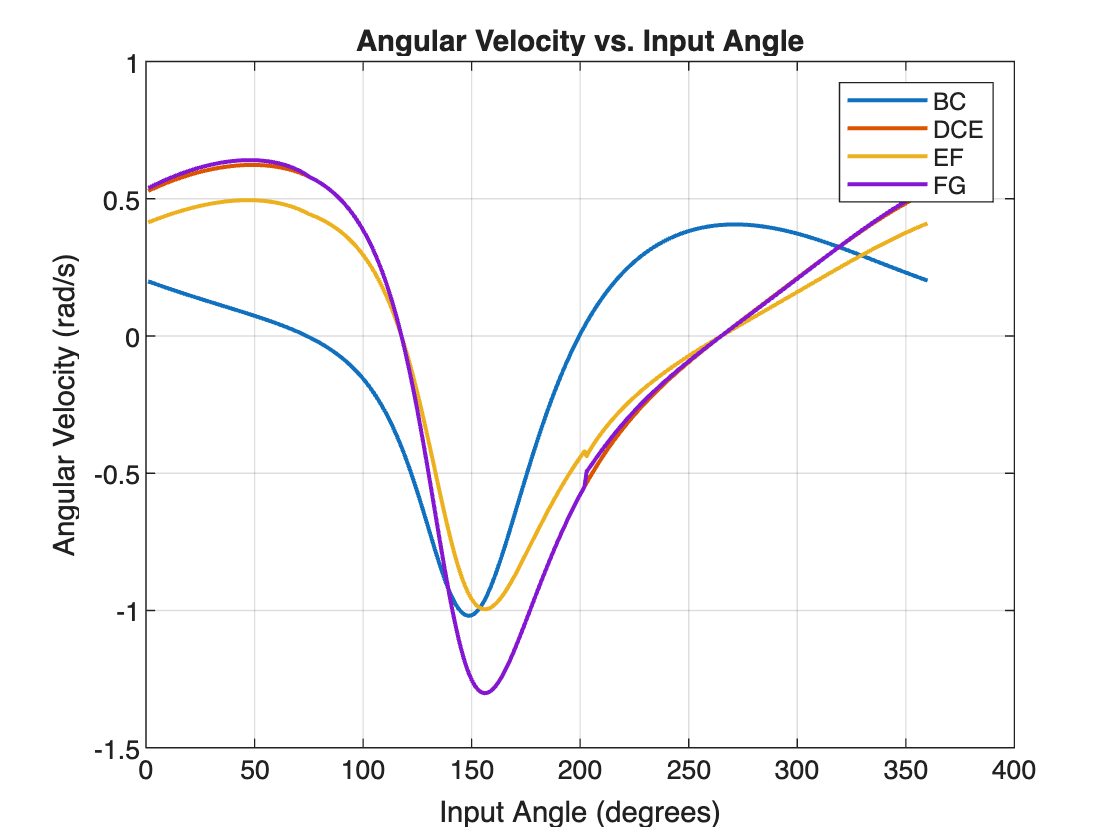





% GRAPH 1: ANGULAR VELOCITY

figure

plot(theta_array,omegaBC_array,'LineWidth',1.5)
hold on
plot(theta_array,omegaDCE_array,'LineWidth',1.5)
plot(theta_array,omegaEF_array,'LineWidth',1.5)
plot(theta_array,omegaFG_array,'LineWidth',1.5)

xlabel('Input Angle (degrees)')
ylabel('Angular Velocity (rad/s)')
title('Angular Velocity vs. Input Angle')

legend('BC','DCE','EF','FG')
grid on
hold off

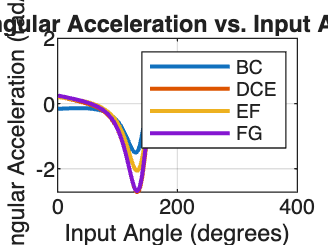



% GRAPH 2: ANGULAR ACCELERATION

figure

plot(theta_array,alphaBC_array,'LineWidth',1.5)
hold on
plot(theta_array,alphaDCE_array,'LineWidth',1.5)
plot(theta_array,alphaEF_array,'LineWidth',1.5)
plot(theta_array,alphaFG_array,'LineWidth',1.5)

xlabel('Input Angle (degrees)')
ylabel('Angular Acceleration (rad/s^2)')
title('Angular Acceleration vs. Input Angle')

legend('BC','DCE','EF','FG')
grid on
hold off

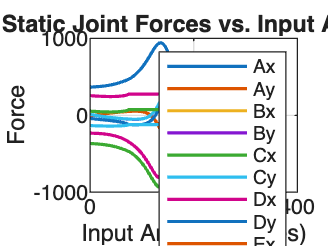



% GRAPH 3: STATIC FORCES

figure

plot(theta_array,Force_Ax_array,'LineWidth',1.2)
hold on
plot(theta_array,Force_Ay_array,'LineWidth',1.2)

plot(theta_array,Force_Bx_array,'LineWidth',1.2)
plot(theta_array,Force_By_array,'LineWidth',1.2)

plot(theta_array,Force_Cx_array,'LineWidth',1.2)
plot(theta_array,Force_Cy_array,'LineWidth',1.2)

plot(theta_array,Force_Dx_array,'LineWidth',1.2)
plot(theta_array,Force_Dy_array,'LineWidth',1.2)

plot(theta_array,Force_Ex_array,'LineWidth',1.2)
plot(theta_array,Force_Ey_array,'LineWidth',1.2)

plot(theta_array,Force_Fx_array,'LineWidth',1.2)
plot(theta_array,Force_Fy_array,'LineWidth',1.2)

plot(theta_array,Force_Gx_array,'LineWidth',1.2)
plot(theta_array,Force_Gy_array,'LineWidth',1.2)

xlabel('Input Angle (degrees)')
ylabel('Force')
title('Static Joint Forces vs. Input Angle')

legend('Ax','Ay','Bx','By','Cx','Cy',...
       'Dx','Dy','Ex','Ey','Fx','Fy','Gx','Gy')

grid on
hold off

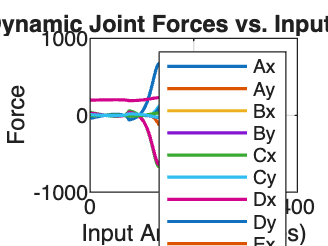



% GRAPH 4: DYNAMIC FORCES

figure

plot(theta_array,NForce_Ax_array,'LineWidth',1.2)
hold on
plot(theta_array,NForce_Ay_array,'LineWidth',1.2)

plot(theta_array,NForce_Bx_array,'LineWidth',1.2)
plot(theta_array,NForce_By_array,'LineWidth',1.2)

plot(theta_array,NForce_Cx_array,'LineWidth',1.2)
plot(theta_array,NForce_Cy_array,'LineWidth',1.2)

plot(theta_array,NForce_Dx_array,'LineWidth',1.2)
plot(theta_array,NForce_Dy_array,'LineWidth',1.2)

plot(theta_array,NForce_Ex_array,'LineWidth',1.2)
plot(theta_array,NForce_Ey_array,'LineWidth',1.2)

plot(theta_array,NForce_Fx_array,'LineWidth',1.2)
plot(theta_array,NForce_Fy_array,'LineWidth',1.2)

plot(theta_array,NForce_Gx_array,'LineWidth',1.2)
plot(theta_array,NForce_Gy_array,'LineWidth',1.2)

xlabel('Input Angle (degrees)')
ylabel('Force')
title('Dynamic Joint Forces vs. Input Angle')

legend('Ax','Ay','Bx','By','Cx','Cy',...
       'Dx','Dy','Ex','Ey','Fx','Fy','Gx','Gy')

grid on
hold off

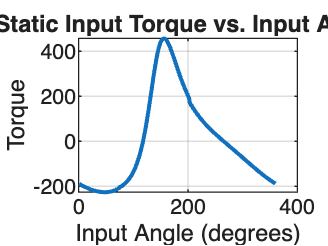



% GRAPH 5: STATIC INPUT TORQUE

figure

plot(theta_array,staticTorque_array,'LineWidth',1.5)

xlabel('Input Angle (degrees)')
ylabel('Torque')
title('Static Input Torque vs. Input Angle')

grid on

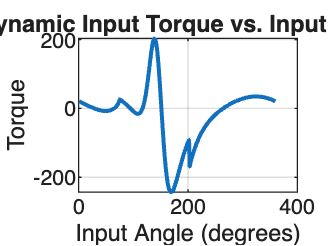


% GRAPH 6: DYNAMIC INPUT TORQUE

figure

plot(theta_array,dynamicTorque_array,'LineWidth',1.5)

xlabel('Input Angle (degrees)')
ylabel('Torque')
title('Dynamic Input Torque vs. Input Angle')

grid on

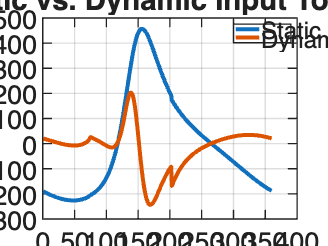



% GRAPH 7: STATIC VS DYNAMIC TORQUE

figure

plot(theta_array,staticTorque_array,'LineWidth',1.5)
hold on
plot(theta_array,dynamicTorque_array,'LineWidth',1.5)

xlabel('Input Angle (degrees)')
ylabel('Torque')
title('Static vs. Dynamic Input Torque')

legend('Static','Dynamic')
grid on
hold off

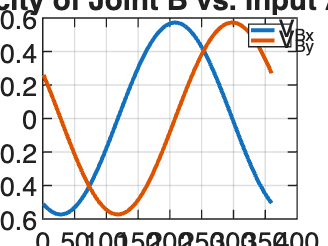



% GRAPH 8: VELOCITY OF B

figure

plot(theta_array,vB_A_x_array,'LineWidth',1.5)
hold on
plot(theta_array,vB_A_y_array,'LineWidth',1.5)

xlabel('Input Angle (degrees)')
ylabel('Velocity')
title('Velocity of Joint B vs. Input Angle')

legend('V_B_x','V_B_y')
grid on
hold off

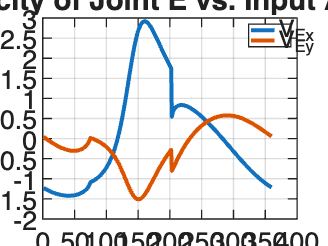



% GRAPH 9: VELOCITY OF E

figure

plot(theta_array,vE_A_x_array,'LineWidth',1.5)
hold on
plot(theta_array,vE_A_y_array,'LineWidth',1.5)

xlabel('Input Angle (degrees)')
ylabel('Velocity')
title('Velocity of Joint E vs. Input Angle')

legend('V_E_x','V_E_y')
grid on
hold off

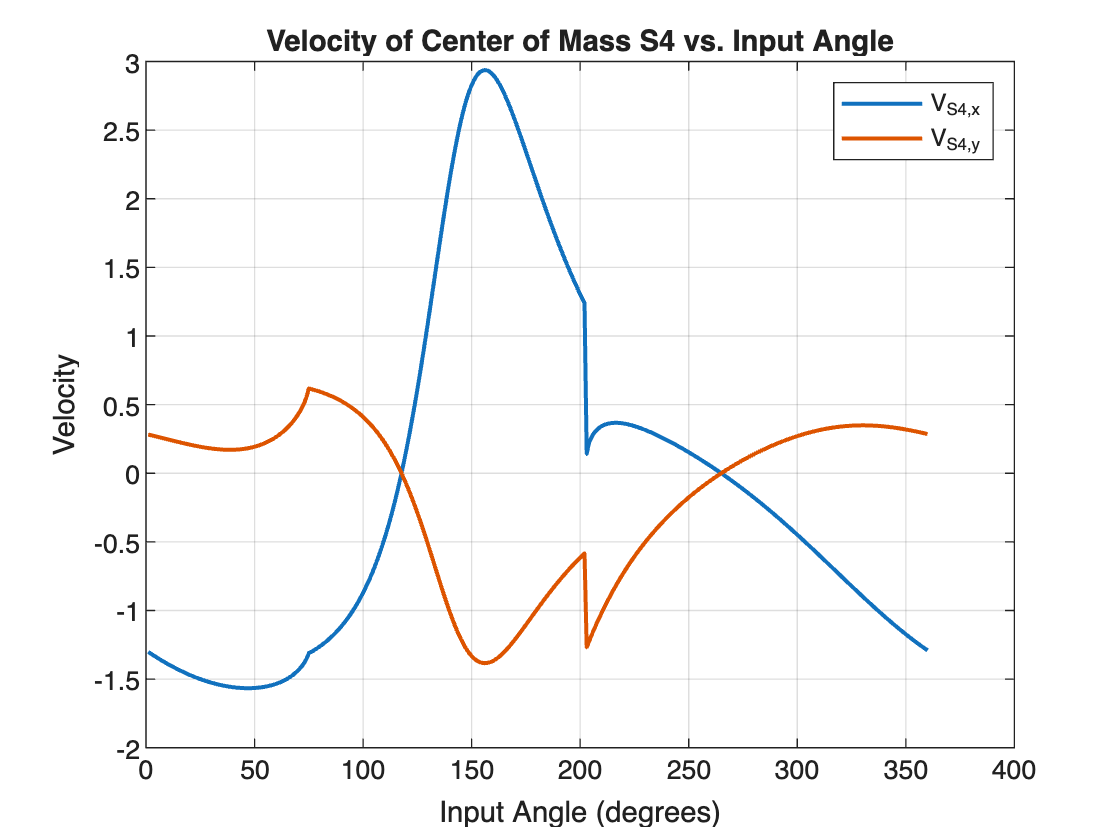



% GRAPH 10: VELOCITY OF S4

figure

plot(theta_array,vS4_G_x_array,'LineWidth',1.5)
hold on
plot(theta_array,vS4_G_y_array,'LineWidth',1.5)

xlabel('Input Angle (degrees)')
ylabel('Velocity')
title('Velocity of Center of Mass S4 vs. Input Angle')

legend('V_{S4,x}','V_{S4,y}')
grid on
hold off